
clear;
clc;


## controller design reset


U_sig = 0;
V_sig = 0;
psi_sig = 0;


## U surge

## Transfer function for black box

(2 m/s aded noise with noise)

% loade moddellenn 
Sim_Time = 200;
U_sig = 1;
V_sig = 0;
psi_sig = 0;

model = "simulink_30_03"

model = "simulink_30_03"

ans =
alpha =      8

     0

ans =
F1 =      5

  132.6948

ans =
alpha =      8

     0

ans =
F1 =      5

  195.0750

ans =
alpha =      8

     0

ans =
F1 =      5

  102.9551

ans =
alpha =      8

     0

ans =
F1 =      5

  159.2702

ans =
alpha =      8

     0

ans =
F1 =      5

  128.4428

ans =
alpha =      8

     0

ans =
F1 =      5

  113.7869

ans =
alpha =      8

     0

ans =
F1 =      5

  101.5799

ans =
alpha =      8

     0

ans =
F1 =      5

  126.9190

ans =
alpha =      8

     0

ans =
F1 =      5

  138.7059

ans =
alpha =      8

     0

ans =
F1 =      5

  129.9147

ans =
alpha =      8

     0

ans =
F1 =      5

  136.8886

ans =
alpha =      8

     0

ans =
F1 =      5

  136.4924

ans =
alpha =      8

     0

ans =
F1 =      5

  119.8814

ans =
alpha =      8

     0

ans =
F1 =      5

  158.2984

ans =
alpha =      8

     0

ans =
F1 =      5

  110.7245

ans =
alpha =      8

     0

ans =
F1 =      5

   77.9802

ans =
alpha =      8

  

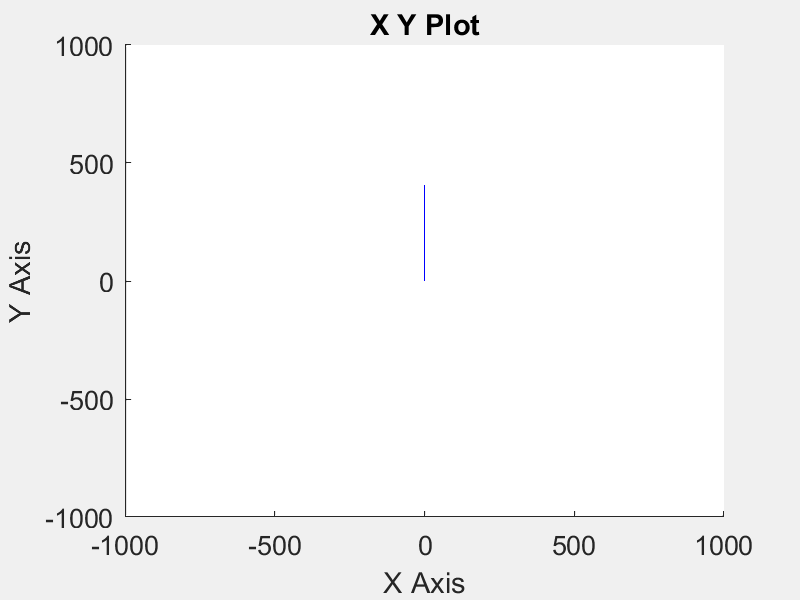

load_system(model);
open_system(model);

sim(model,Sim_Time)

% design
input_u = vel_u_input.Data;
output_u = vel_u_output.Data;



count=1;
output_u_updated = zeros(length(input_u),1);

% uses modulus 
for i = 1:length(output_u) 
   if mod(i,5) == 0
       output_u_updated(count) = output_u(i);
       count = count+1;
   end
end
output_u_updated(length(input_u)) = output_u(length(output_u));

% updated output
output_u_updated;


%tf = tfestimate(input_u,output_u_updated)

%bode(tf)

%tf = tfestimate(vel_u_input,vel_u_output)



output_u_updated = output_u_updated(1001:2001)
input_u = input_u(1001:2001)



% create iddata object by specifying output signal, input signal, and sampling time
sample_time = 0.1;
%data=iddata(output_u_updated,input_u);
data=iddata(output_u_updated,input_u,sample_time);
% estimate a transfer function with 2 poles and 1 zero
sys=tfest(data,2,1)


poles_sys = pole(sys)
zeros_sys = zero(sys)

bode(sys)
grid on
step(sys)
grid on

margin(sys)
grid on

G = sys;





% design
input_u = vel_u_input.Data;
output_u = vel_u_output.Data;



count=1;
output_u_updated = zeros(length(input_u),1);

% uses modulus 
for i = 1:length(output_u) 
   if mod(i,5) == 0
       output_u_updated(count) = output_u(i);
       count = count+1;
   end
end
output_u_updated(length(input_u)) = output_u(length(output_u));

% updated output
output_u_updated;


%tf = tfestimate(input_u,output_u_updated)

%bode(tf)

%tf = tfestimate(vel_u_input,vel_u_output)



output_u_updated = output_u_updated(1001:2001)
input_u = input_u(1001:2001)



% create iddata object by specifying output signal, input signal, and sampling time
sample_time = 0.1;
%data=iddata(output_u_updated,input_u);
data=iddata(output_u_updated,input_u,sample_time);
% estimate a transfer function with 2 poles and 1 zero
sys=tfest(data,1,1)


poles_sys = pole(sys)
zeros_sys = zero(sys)

bode(sys)
grid on
step(sys)
grid on

margin(sys)
grid on

G = sys;










## P- regulator


dbmag = 6
Kp = 10^(dbmag/20) %ca -17 aflæses fra bode plottet ved -180+fasemargin(60)
%så ved -120. samme frekvens findes i magnitude plottet, og dB aflæses 
%disp(Kp);


Gol_P = Kp*G
bode(Gol_P)
grid on
step(Gol_P)
grid on

poles_P = pole(Gol_P)
zeros_P = zero(Gol_P)


## med lukket sløjfe


%Kp_up = Kp * 25
Kp_up = Kp * 2
Kp_up = 2
Kp_up = Kp

G_up = minreal(Kp_up*G/(1+G*Kp_up),1.0e-5)
step(G_up)

## PI ud fra phasen


%vælger fasen ved -60 grader -> vi ligger nulpunktet i i-ledet 5-10 gange
%lavere end fasemargin frekvensen for en p-kontroller 
% sørg for at den endelige phasemargin er under 180- meget vigtigt, men det
% er på den endelige bode

bode(G)

% sim er 50Hz så båndbredden skal være omkring 10 gange lavere  

omega_c = 1.9;
%omega_c = 0.9;

%omega_c = 5;
%omega_c =0.65; %  rykket grunet for højt thrust
tau_i = 1/omega_c
%tau_i = 1.53

% Controller transfer
Ci = tf([tau_i 1],[tau_i 0]);     % I and PI zero
Gol_PI = Ci*G                    % open loop

bode(Gol_PI)


dbmag = 16%20.6 % rykker den en smule mere op i frekvens (er stadig under 180)
%dbmag = 22
%dmag = 1.5

Kp = 10^(dbmag/20) %ca -17 aflæses fra bode plottet ved -180+fasemargin(60)

% kp = 2
% kp = 4
% kp = 0.1001
%så ved -120. samme frekvens findes i magnitude plottet, og dB aflæses 
%disp(Kp);
%Kp = 2
%Kp = 17
%Kp = 2.5586

Gol_PI_p = Kp*Ci*G                    % open loop

bode(Gol_PI_p)

G_close = minreal(Gol_PI_p/(1+Gol_PI_p),0.1e-5)
step(G_close)



## Design af PID

## Ud fra phase


%vælger fasen ved -60 grader -> vi ligger nulpunktet i i-ledet 5-10 gange
%lavere end fasemargin frekvensen for en p-kontroller 
% sørg for at den endelige phasemargin er under 180- meget vigtigt, men det
% er på den endelige bode

alpha = 0.05;
%alpha = 0.1;


bode(G)

% sim er 50Hz så båndbredden skal være omkring 10 gange lavere  

omega_c = 3;
tau_i = 1/omega_c
tau_d = 1/(omega_c*sqrt(alpha))

% Controller transfer
Ci = tf([tau_i 1],[tau_i 0]);         % I and PI zero
Cd = tf([tau_d 1],[alpha*tau_d 1]);   % lead
Gol_PID_phase = Ci*Cd*G                      % open loop

bode(Gol_PID_phase)



dbmag = 7.7 % rykker den en smule mere op i frekvens (er stadig under 180)
%dbmag = 22

Kp = 10^(dbmag/20) %ca -17 aflæses fra bode plottet ved -180+fasemargin(60)
%så ved -120. samme frekvens findes i magnitude plottet, og dB aflæses 
%disp(Kp);

%kp = 1.5



Gol_PID_p = Kp*Cd*Ci*G                    % open loop

bode(Gol_PID_p)

G_close = minreal(Gol_PID_p/(1+Gol_PID_p),0.1e-5)
step(G_close)













## PD

alpha    = 2;
gamma_m  = 60; % fasemargin

phi_lead = asin((1-alpha)/(1+alpha))*180/pi;
arg      = -180 + gamma_m -phi_lead - phi_PI

% aflæs i phase plot på phase(arg) 
omega_c  = 0.077337;
%omega_c  = 1;

tau_d    = 1/(omega_c*sqrt(alpha))

% aflæses ved fasemargin som ved p regulator blot i + da vi ønsker et løft 
% figure
% bode(G);
% grid on

%hvor meget ønsker vi at løfte eller sænke? (+ for løfte, - for sænke)
dbmag=0.001
Kp = 10^(dbmag/20)




% Controller transfer

Cd = tf([tau_d 1],[alpha*tau_d 1]);   % lead
Gol_PD = Kp*Cd*G                     % open loop


bode(Gol_PD)
grid on 
poles_PD = pole(Gol_PD)
zeros_PD = zero(Gol_PD)
step(Gol_PD)



## V sway

## Transfer function for black box

(1 m/s aded noise with noise)

% loade modellen 
Sim_Time = 200;
U_sig = 0;
V_sig = 1;
psi_sig = 0;

model = "simulink_30_03"

model = "simulink_30_03"

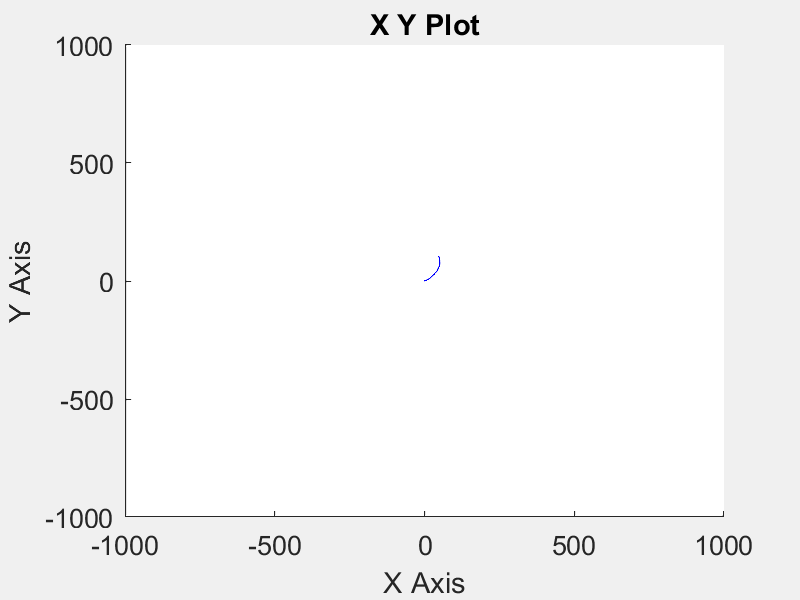

load_system(model);
open_system(model);

sim(model,Sim_Time)

input_v = vel_v_input.Data

input_v =     0.6271
    1.2691
    0.2433
    0.9209
    0.5764
    0.3917
    0.2235
    0.5580
    0.6969
    0.5941


output_v = vel_v_output.Data

output_v =          0
         0
    0.0002
    0.0004
    0.0009
    0.0014
    0.0035
    0.0059
    0.0087
    0.0117




count=1;
output_v_updated = zeros(length(input_v),1);

% uses modulus 
for i = 1:length(output_v) 
   if mod(i,5) == 0
       output_v_updated(count) = output_v(i);
       count = count+1;
   end
end
output_v_updated(length(input_v)) = output_v(length(output_v));

% updated output
output_v_updated

output_v_updated =     0.0009
    0.0117
    0.0166
    0.0291
    0.0393
    0.0453
    0.0486
    0.0569
    0.0698
    0.0813




output_v_updated = output_v_updated(1001:2001)

output_v_updated =     0.5853
    0.5804
    0.5735
    0.5678
    0.5686
    0.5738
    0.5727
    0.5726
    0.5689
    0.5654


input_v = input_v(1001:2001)

input_v =     0.6948
    0.2668
    0.2570
    0.3244
    0.6303
    0.7536
    0.4432
    0.5794
    0.3587
    0.4220




%tf = tfestimate(input_u,output_u_updated)

%bode(tf)

%tf = tfestimate(vel_u_input,vel_u_output)


% create iddata object by specifying output signal, input signal, and sampling time
sample_time = 0.1;
%data=iddata(output_u_updated,input_u);
data=iddata(output_v_updated,input_v,sample_time);
% estimate a transfer function with 2 poles and 1 zero
sys=tfest(data,2,1)

sys =
 
  From input "u1" to output "y1":
     0.2571 s + 0.03816
  ------------------------
  s^2 + 0.5096 s + 0.03435
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 1
   Number of free coefficients: 4
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: 66.79%                   
FPE: 7.423e-05, MSE: 7.335e-05                   




poles_sys = pole(sys)

poles_sys =    -0.4297
   -0.0799


zeros_sys = zero(sys)

zeros_sys = -0.1484

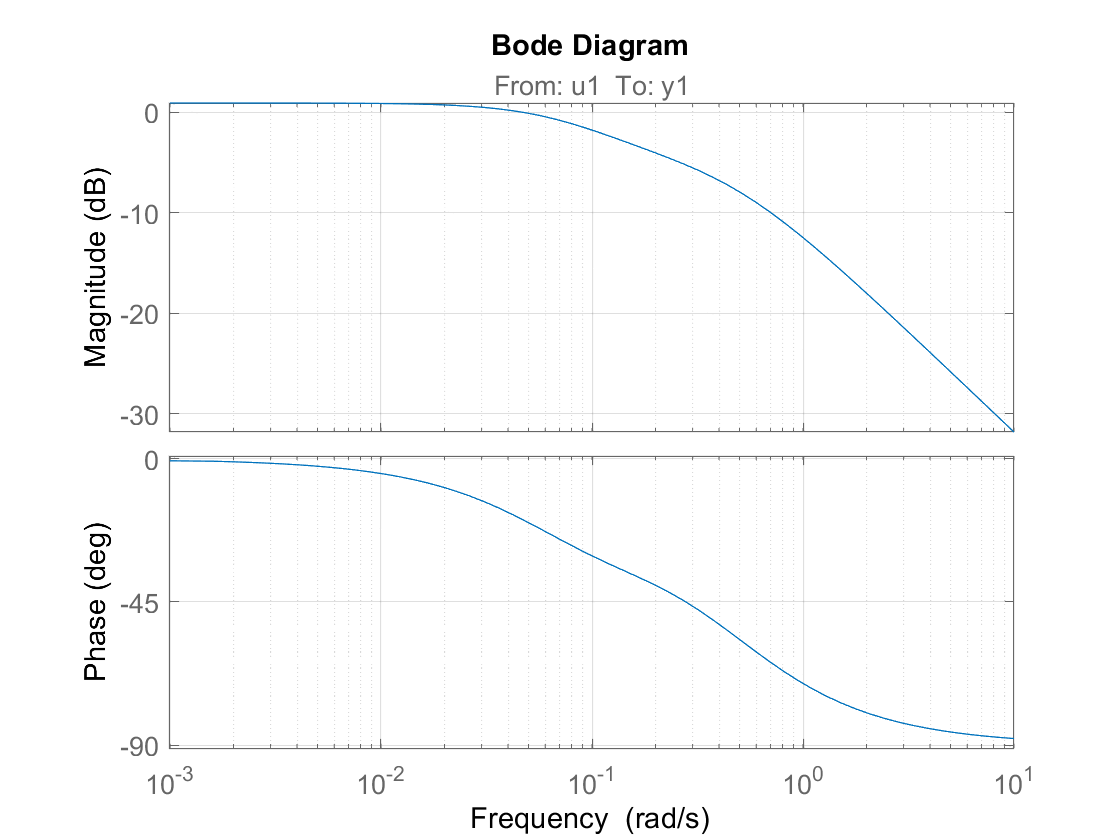


bode(sys)
grid on

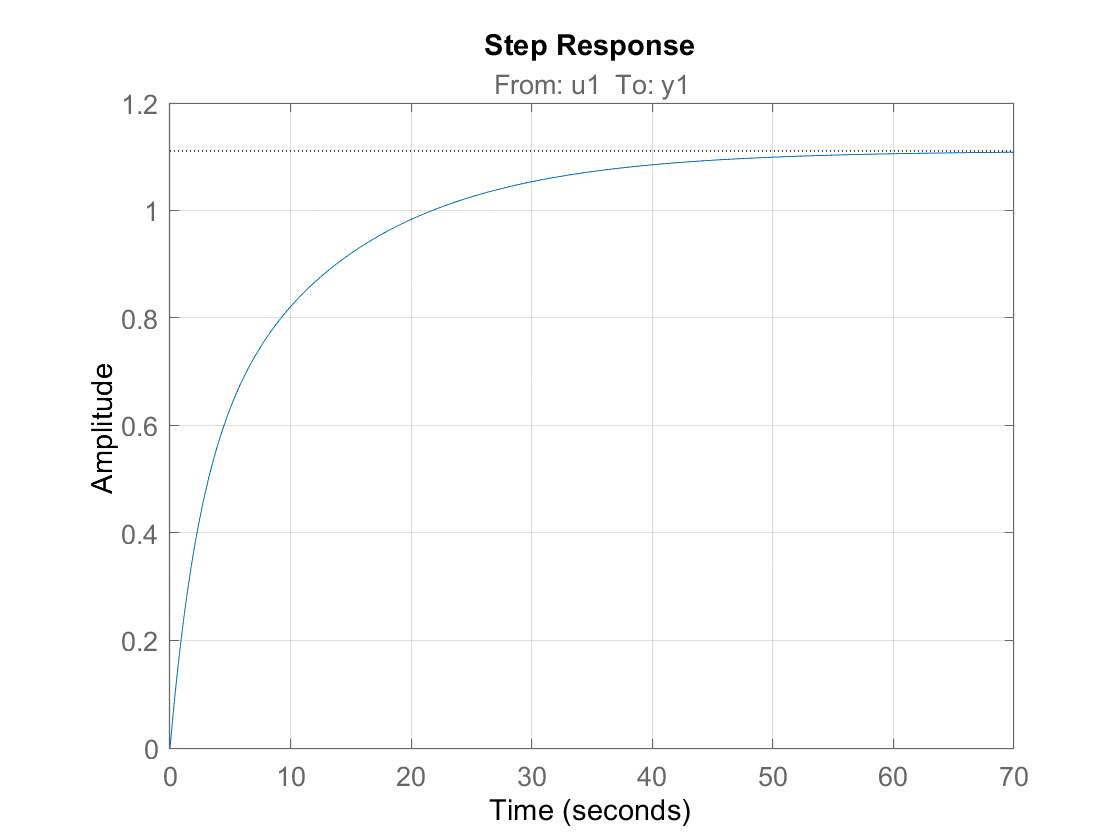

step(sys)
grid on

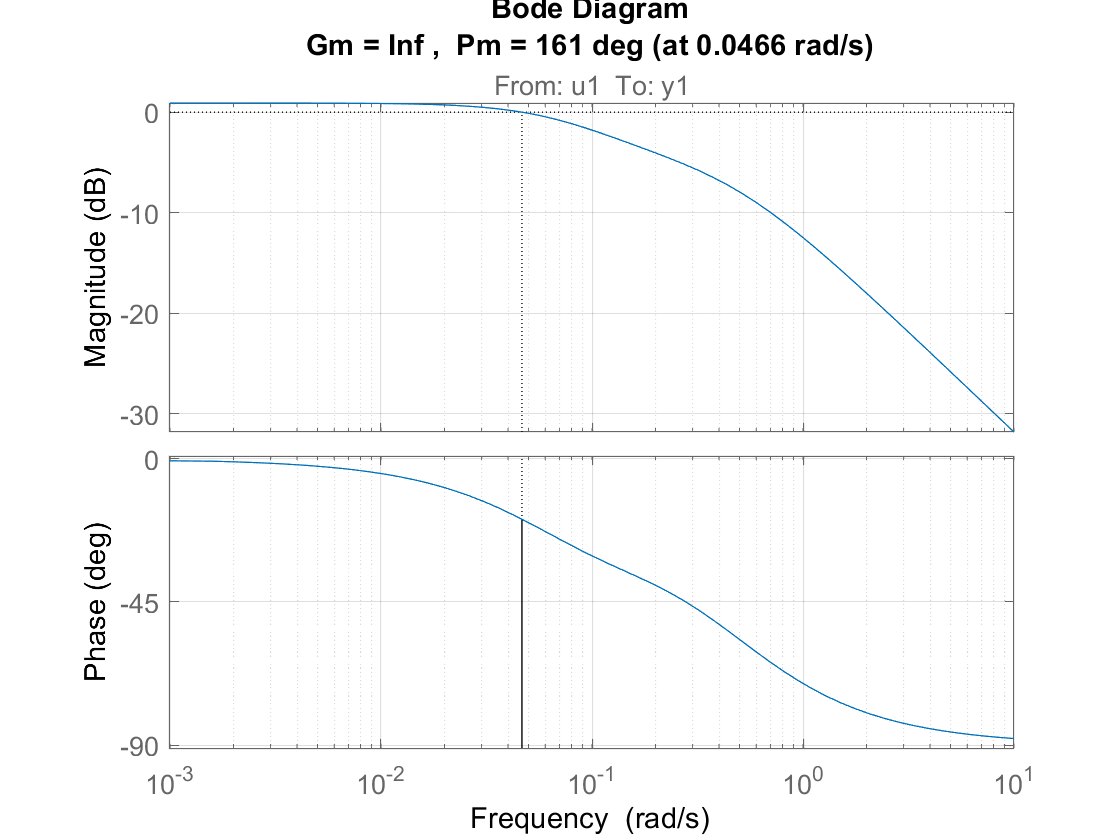


margin(sys)
grid on


G = sys;









input_v = vel_v_input.Data

input_v =     0.6271
    1.2691
    0.2433
    0.9209
    0.5764
    0.3917
    0.2235
    0.5580
    0.6969
    0.5941


output_v = vel_v_output.Data

output_v =          0
         0
    0.0002
    0.0004
    0.0009
    0.0014
    0.0035
    0.0059
    0.0087
    0.0117




count=1;
output_v_updated = zeros(length(input_v),1);

% uses modulus 
for i = 1:length(output_v) 
   if mod(i,5) == 0
       output_v_updated(count) = output_v(i);
       count = count+1;
   end
end
output_v_updated(length(input_v)) = output_v(length(output_v));

% updated output
output_v_updated

output_v_updated =     0.0009
    0.0117
    0.0166
    0.0291
    0.0393
    0.0453
    0.0486
    0.0569
    0.0698
    0.0813




output_v_updated = output_v_updated(1001:2001)

output_v_updated =     0.5853
    0.5804
    0.5735
    0.5678
    0.5686
    0.5738
    0.5727
    0.5726
    0.5689
    0.5654


input_v = input_v(1001:2001)

input_v =     0.6948
    0.2668
    0.2570
    0.3244
    0.6303
    0.7536
    0.4432
    0.5794
    0.3587
    0.4220




%tf = tfestimate(input_u,output_u_updated)

%bode(tf)

%tf = tfestimate(vel_u_input,vel_u_output)


% create iddata object by specifying output signal, input signal, and sampling time
sample_time = 0.1;
%data=iddata(output_u_updated,input_u);
data=iddata(output_v_updated,input_v,sample_time);
% estimate a transfer function with 2 poles and 1 zero
sys=tfest(data,1,1)

sys =
 
  From input "u1" to output "y1":
  0.02067 s + 0.2396
  ------------------
      s + 0.2158
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 1   Number of zeros: 1
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: 70.34%                   
FPE: 5.899e-05, MSE: 5.852e-05                   




poles_sys = pole(sys)

poles_sys = -0.2158

zeros_sys = zero(sys)

zeros_sys = -11.5959

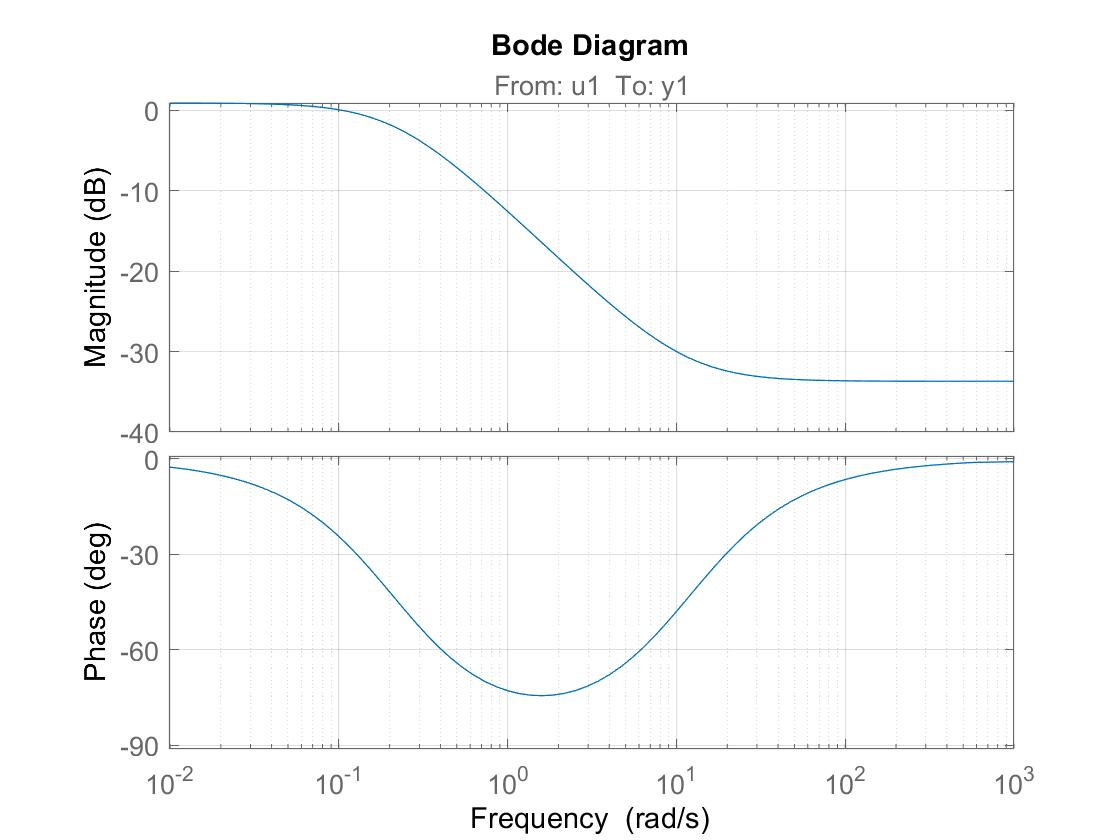


bode(sys)
grid on

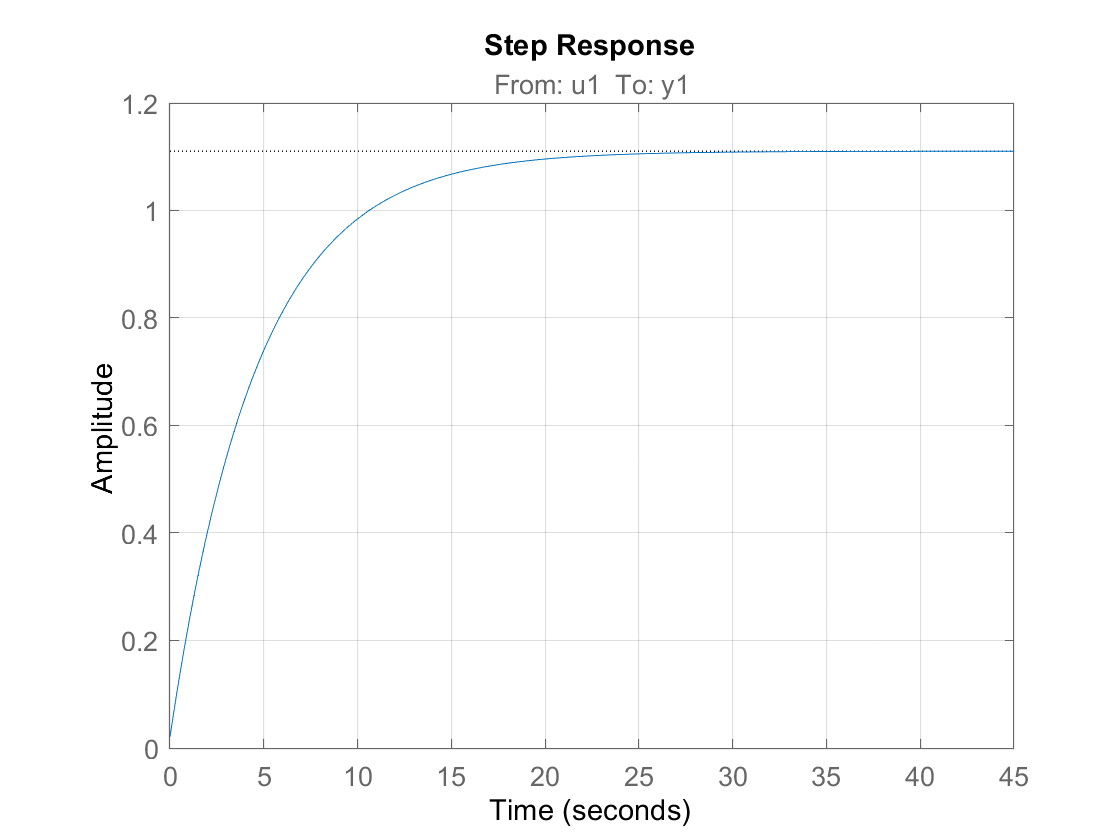

step(sys)
grid on

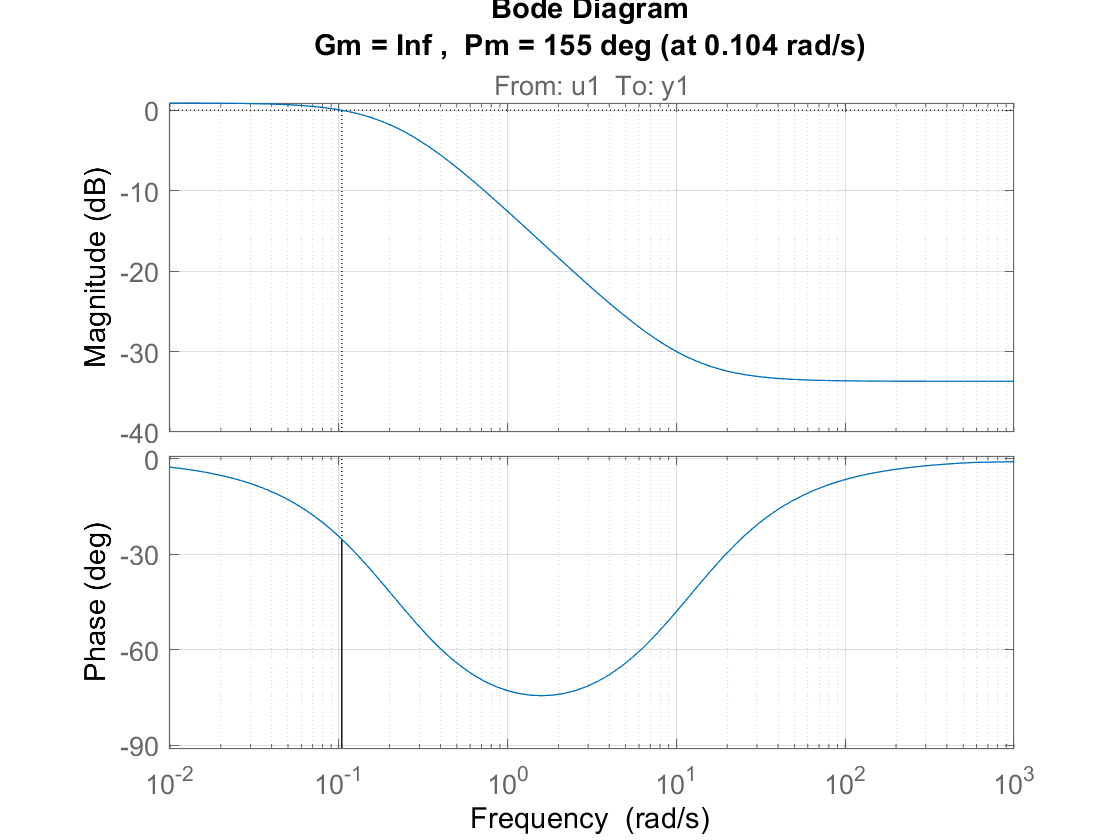


margin(sys)
grid on


G = sys;






## P- regulator


dbmag= -1

dbmag = -1


Kp = 10^(dbmag/20) %ca -17 aflæses fra bode plottet ved -180+fasemargin(60)

Kp = 0.8913

%så ved -120. samme frekvens findes i magnitude plottet, og dB aflæses 
%disp(Kp);


Gol_P = Kp*G

Gol_P =
 
  From input "u1" to output:
  0.01842 s + 0.2136
  ------------------
      s + 0.2158
 
Continuous-time transfer function.



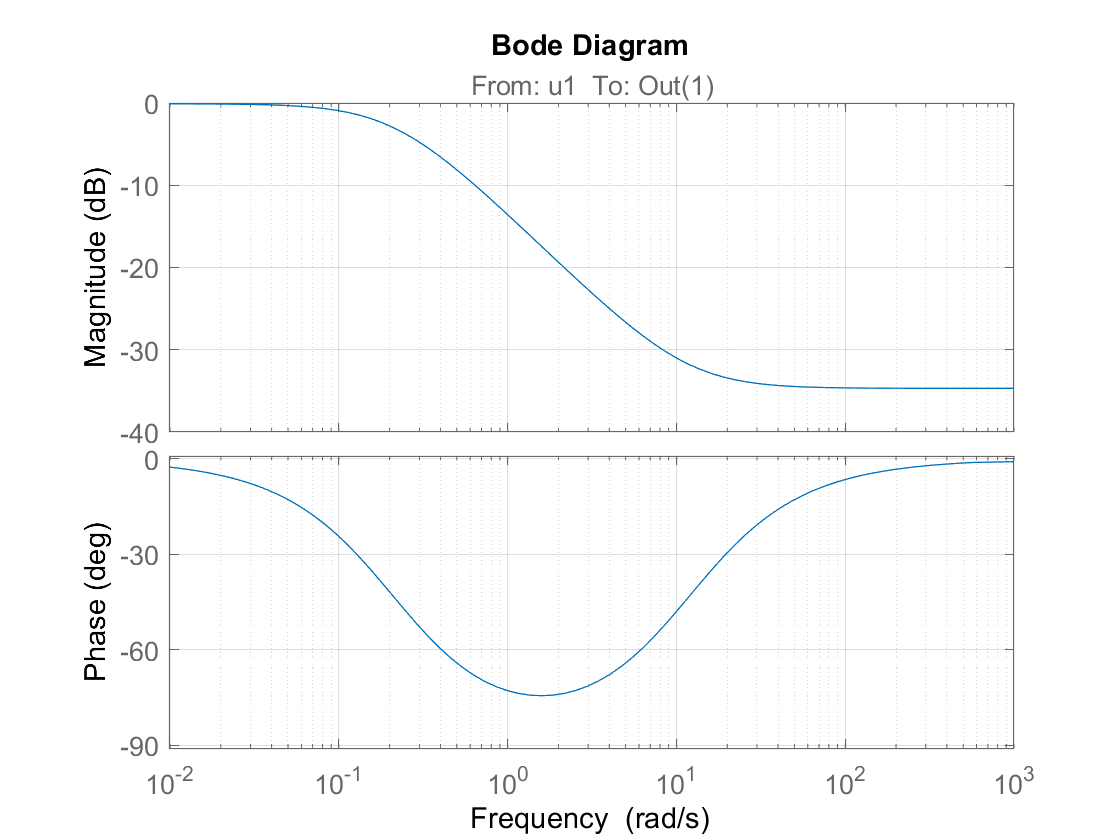

bode(Gol_P)
grid on

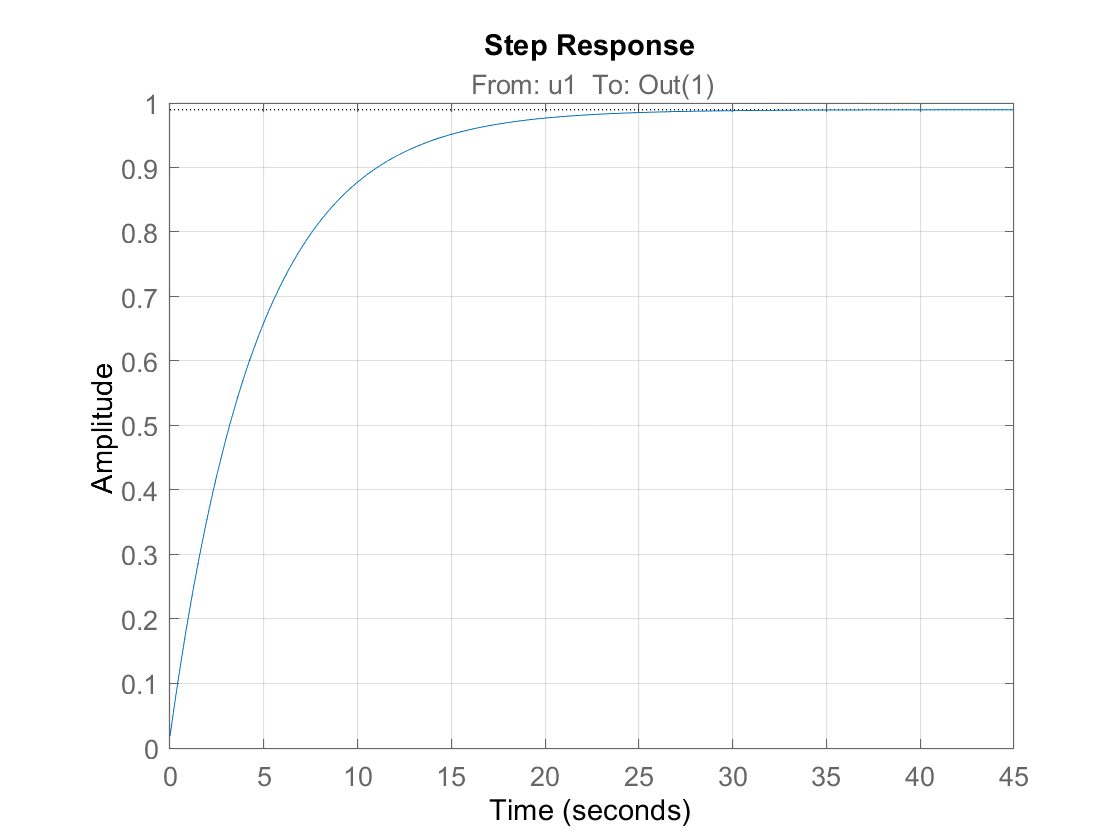

step(Gol_P)
grid on


poles_P = pole(Gol_P)

poles_P = -0.2158

zeros_P = zero(Gol_P)

zeros_P = -11.5959

## med lukket sløjfe


%Kp_up = Kp * 25
Kp_p = Kp * 2

Kp_p = 1.7825

G_p = minreal(Kp_p*G/(1+G*Kp_p),1.0e-5)

G_p =
 
  From input "y1" to output:
  0.03553 s + 0.412
  -----------------
     s + 0.6201
 
Continuous-time transfer function.



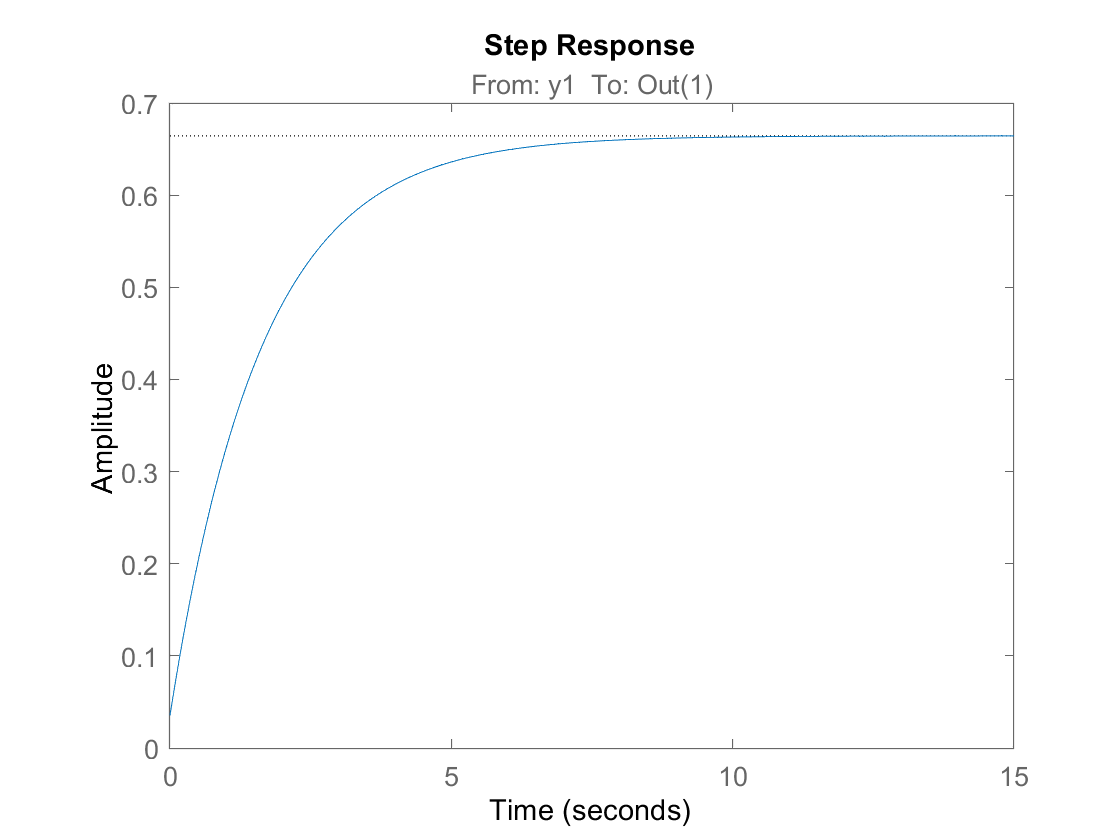

step(G_p)

## PI regulator

## PI ud fra phasen

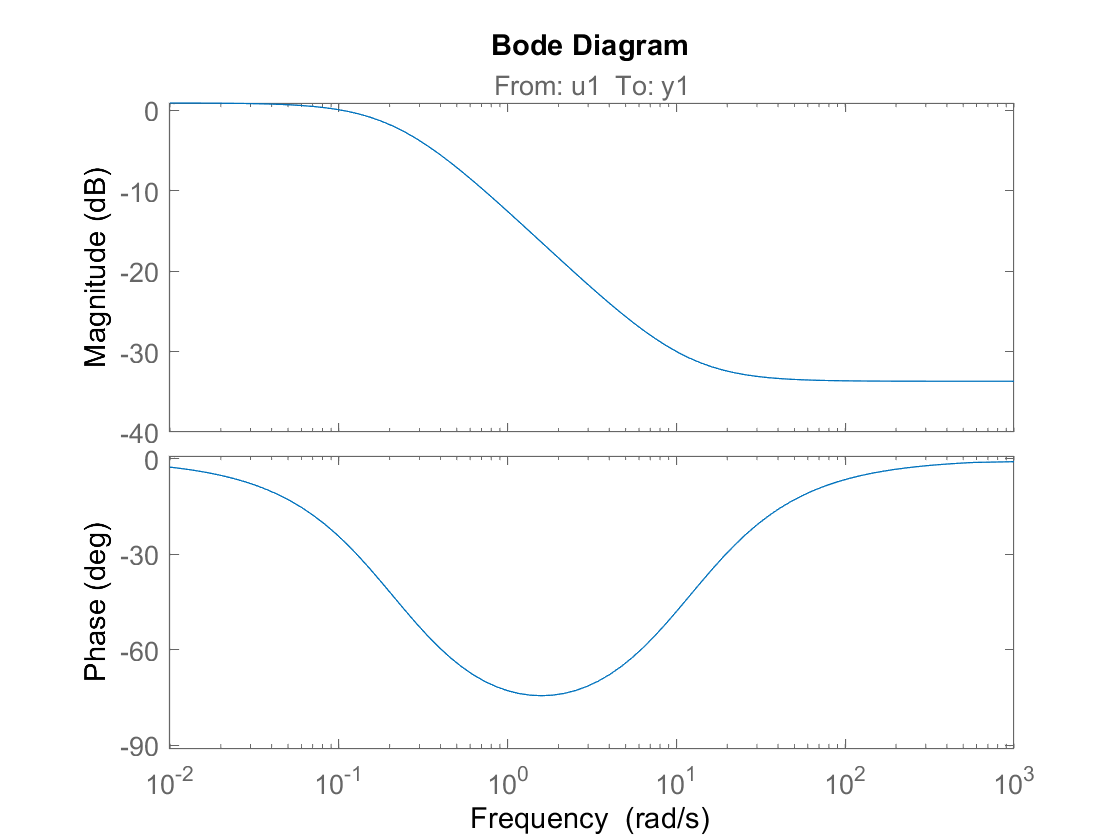


%vælger fasen ved -60 grader -> vi ligger nulpunktet i i-ledet 5-10 gange
%lavere end fasemargin frekvensen for en p-kontroller 
% sørg for at den endelige phasemargin er under 180- meget vigtigt, men det
% er på den endelige bode

bode(G)


% sim er 50Hz så båndbredden skal være omkring 10 gange lavere  

omega_c = 0.9;
omega_c = 2;
tau_i = 1/omega_c

tau_i = 0.5000

%tau_i = 0.5

% Controller transfer
Ci = tf([tau_i 1],[tau_i 0]);     % I and PI zero
Gol_PI = Ci*G                    % open loop

Gol_PI =
 
  From input "u1" to output:
  0.01033 s^2 + 0.1405 s + 0.2396
  -------------------------------
        0.5 s^2 + 0.1079 s
 
Continuous-time transfer function.



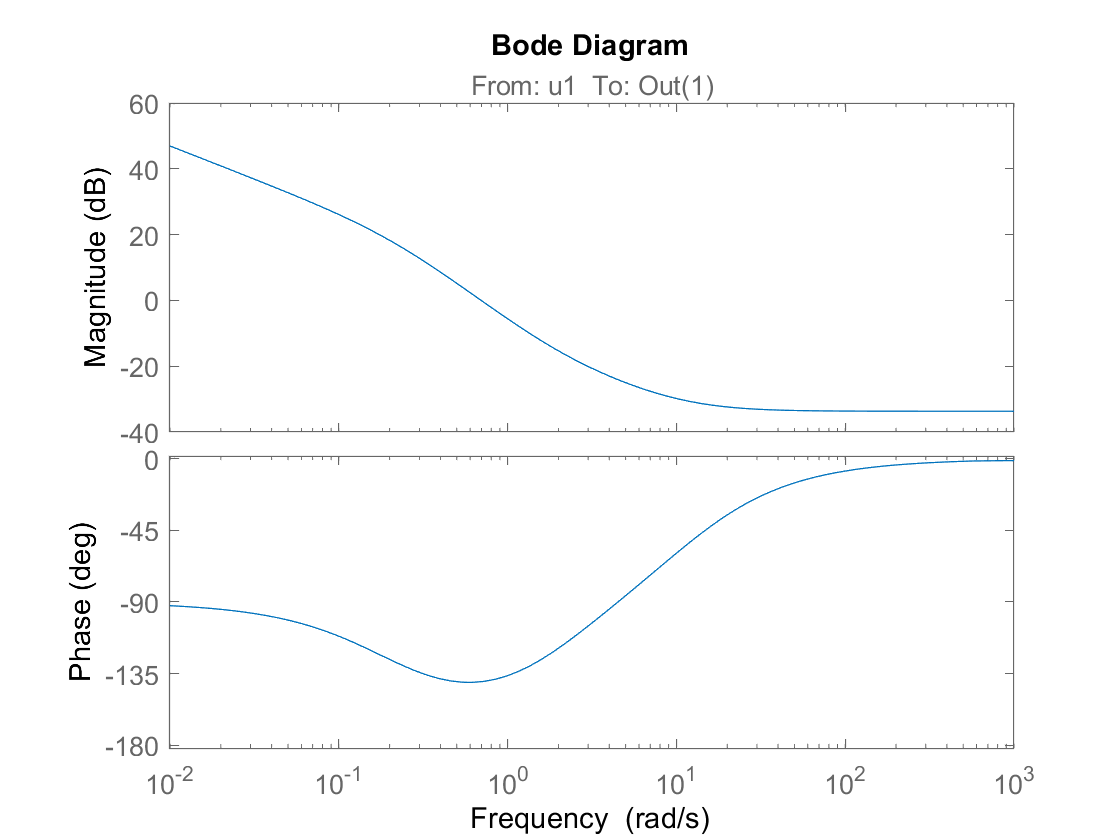


bode(Gol_PI)



dbmag = 23 % rykker den en smule mere op i frekvens (er stadig under 180)

dbmag = 23

%dbmag = 22

Kp = 10^(dbmag/20) %ca -17 aflæses fra bode plottet ved -180+fasemargin(60)

Kp = 14.1254


dbmag = 3.4 % rykker den en smule mere op i frekvens (er stadig under 180)

dbmag = 3.4000

%dbmag = 22

Kp = 10^(dbmag/20) %ca -17 aflæses fra bode plottet ved -180+fasemargin(60)

Kp = 1.4791

%så ved -120. samme frekvens findes i magnitude plottet, og dB aflæses 
%disp(Kp);
%Kp = 2
Kp = 1;

Gol_PI_S = Kp*Ci*G                    % open loop

Gol_PI_S =
 
  From input "u1" to output:
  0.01033 s^2 + 0.1405 s + 0.2396
  -------------------------------
        0.5 s^2 + 0.1079 s
 
Continuous-time transfer function.




bode(Gol_PI_S)


G_close = minreal(Gol_PI_S/(1+Gol_PI_S),0.1e-5)

G_close =
 
  0.02025 s^2 + 0.2753 s + 0.4696
  -------------------------------
      s^2 + 0.4867 s + 0.4696
 
Continuous-time transfer function.



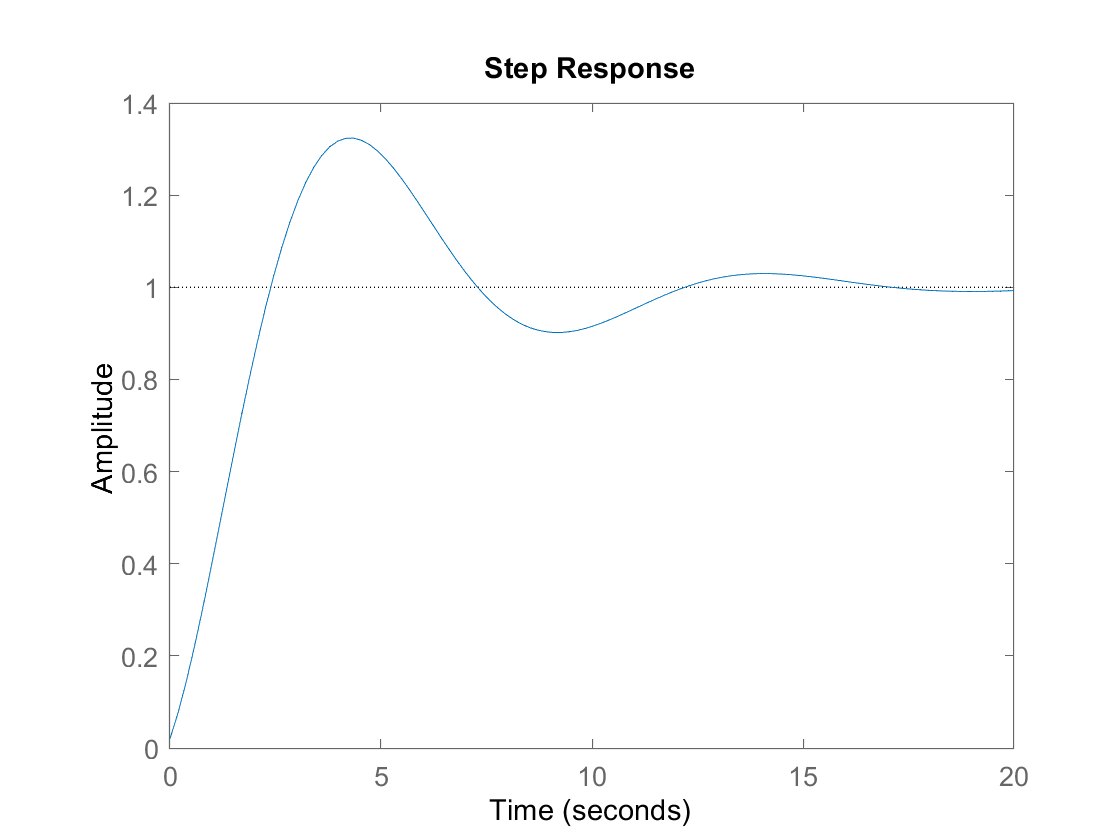

step(G_close)

## PID Ud fra phase


%vælger fasen ved -60 grader -> vi ligger nulpunktet i i-ledet 5-10 gange
%lavere end fasemargin frekvensen for en p-kontroller 
% sørg for at den endelige phasemargin er under 180- meget vigtigt, men det
% er på den endelige bode

alpha = 0.05; % 0.2


bode(G)


% sim er 50Hz så båndbredden skal være omkring 10 gange lavere  

omega_c = 1.2;
omega_c = 3;
%omega_c = 0.9;
tau_i = 1/omega_c

tau_i = 0.3333

tau_d = 1/(omega_c*sqrt(alpha))

tau_d = 1.4907


% Controller transfer
Ci = tf([tau_i 1],[tau_i 0]);         % I and PI zero
Cd = tf([tau_d 1],[alpha*tau_d 1]);   % lead
Gol_PID_phase = Ci*Cd*G               % open loop

Gol_PID_phase =
 
  From input "u1" to output:
  0.01027 s^3 + 0.1568 s^2 + 0.4578 s + 0.2396
  --------------------------------------------
      0.02485 s^3 + 0.3387 s^2 + 0.07194 s
 
Continuous-time transfer function.



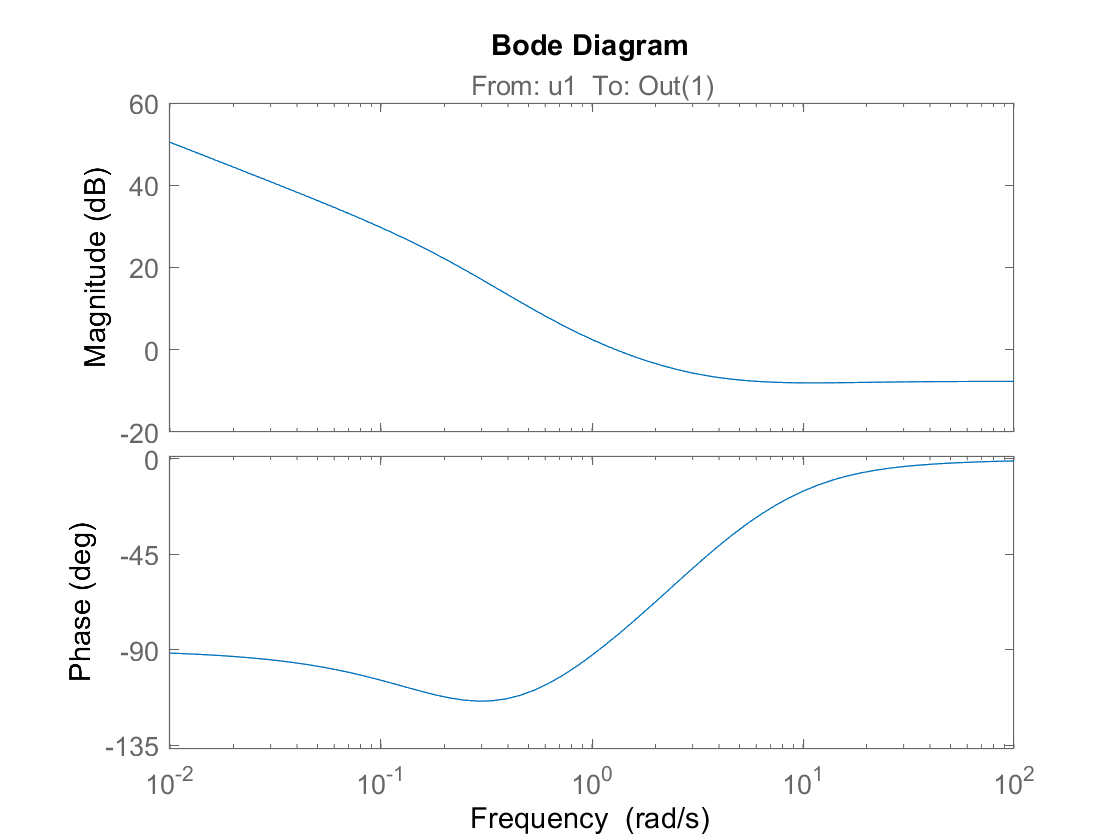


bode(Gol_PID_phase)




dbmag = 15 % rykker den en smule mere op i frekvens (er stadig under 180)

dbmag = 15

dbmag = 4

dbmag = 4


Kp = 10^(dbmag/20) %ca -17 aflæses fra bode plottet ved -180+fasemargin(60)

Kp = 1.5849

%så ved -120. samme frekvens findes i magnitude plottet, og dB aflæses 
%disp(Kp);

Gol_PID_p = Kp*Cd*Ci*G                    % open loop

Gol_PID_p =
 
  From input "u1" to output:
  0.01628 s^3 + 0.2485 s^2 + 0.7255 s + 0.3798
  --------------------------------------------
      0.02485 s^3 + 0.3387 s^2 + 0.07194 s
 
Continuous-time transfer function.



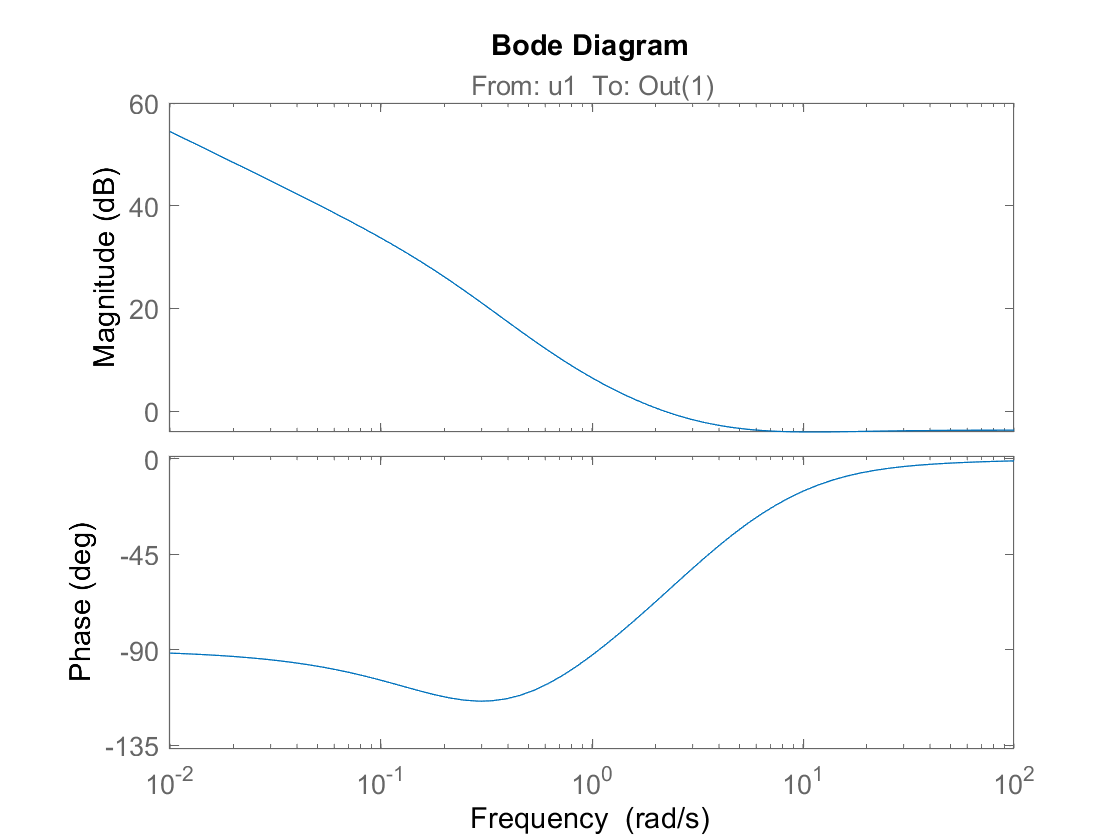


bode(Gol_PID_p)


G_close = minreal(Gol_PID_p/(1+Gol_PID_p),0.1e-5)

G_close =
 
  0.3958 s^3 + 6.042 s^2 + 17.64 s + 9.236
  ----------------------------------------
     s^3 + 14.28 s^2 + 19.39 s + 9.236
 
Continuous-time transfer function.



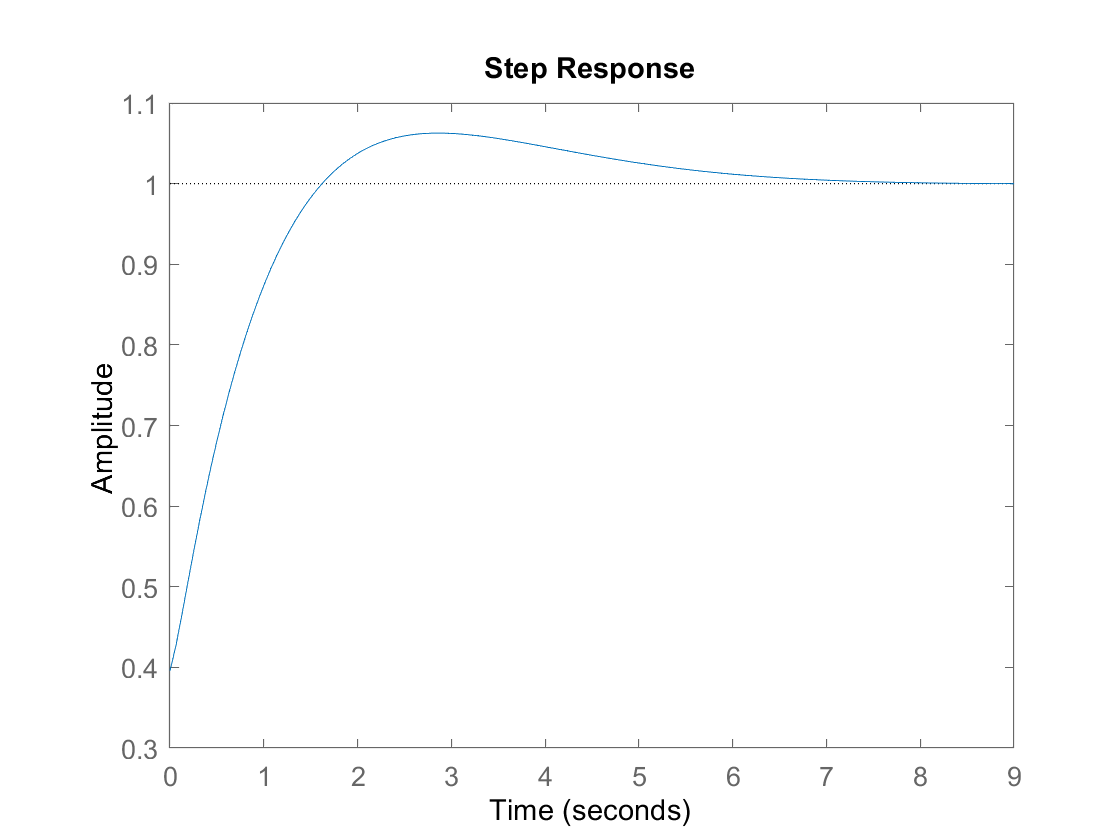

step(G_close)

## PD

alpha    = 2;
gamma_m  = 60; % fasemargin

phi_lead = asin((1-alpha)/(1+alpha))*180/pi;
arg      = -180 + gamma_m -phi_lead - phi_PI

% aflæs i phase plot på phase(arg) 
omega_c  = 0.077337;
%omega_c  = 1;

tau_d    = 1/(omega_c*sqrt(alpha))

%hvor meget ønsker vi at løfte eller sænke? (+ for løfte, - for sænke)
dbmag = 0.55
Kp = 10^(dbmag/20)


% Controller transfer
Cd = tf([tau_d 1],[alpha*tau_d 1]);   % lead
Gol_PD = Kp*Cd*G                     % open loop


bode(Gol_PD)
grid on 
poles_PD = pole(Gol_PD)
zeros_PD = zero(Gol_PD)
step(Gol_PD)



## r angle velocity

## Transfer function for black box

(90 degrees (pi/2))

% loader modellen 
Sim_Time = 200;
U_sig = 0;
V_sig = 0;
psi_sig = 1;

model = "simulink_30_03"

model = "simulink_30_03"

ans =
alpha =      8

     0

ans =
F1 =      5

  826.4853

ans =
alpha =      8

     0

ans =
F1 =      5

   2.6735e+03

ans =
alpha =      8

     0

ans =
F1 =      5

 -277.9464

ans =
alpha =      8

     0

ans =
F1 =      5

   1.6715e+03

ans =
alpha =      8

     0

ans =
F1 =      5

  680.6258

ans =
alpha =      8

     0

ans =
F1 =      5

  149.2333

ans =
alpha =      8

     0

ans =
F1 =      5

 -334.6938

ans =
alpha =      8

     0

ans =
F1 =      5

  627.5121

ans =
alpha =      8

     0

ans =
F1 =      5

   1.0272e+03

ans =
alpha =      8

     0

ans =
F1 =      5

  731.5016

ans =
alpha =      8

     0

ans =
F1 =      5

  967.1417

ans =
alpha =      8

     0

ans =
F1 =      5

  953.9847

ans =
alpha =      8

     0

ans =
F1 =      5

  376.0163

ans =
alpha =      8

     0

ans =
F1 =      5

   1.6424e+03

ans =
alpha =      8

     0

ans =
F1 =      5

   31.7866

ans =
alpha =      8

     0

ans =
F1 =      5

  -1.4291e+03

ans =
alp

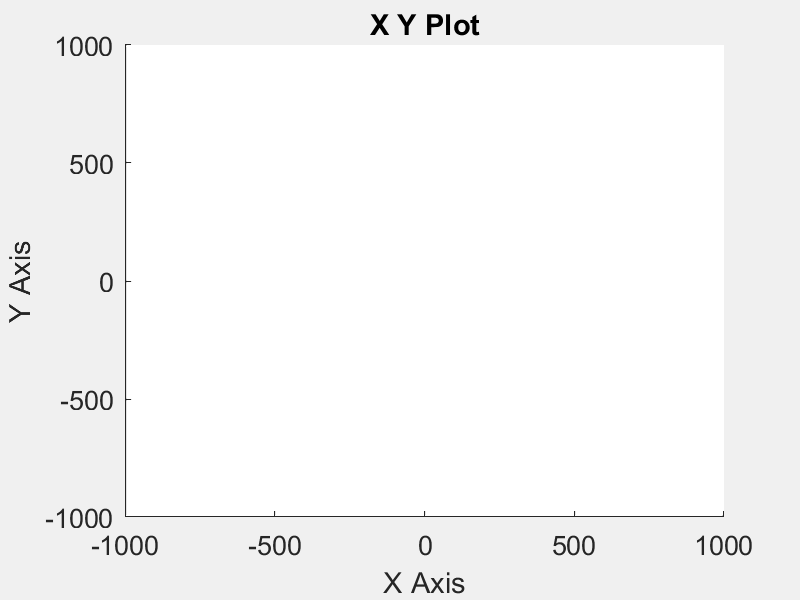

load_system(model);
open_system(model);

sim(model,Sim_Time)


d = 1

input_angle = angle_input.Data

input_angle =     0.2873
    0.9293
   -0.0966
    0.5810
    0.2366
    0.0519
   -0.1163
    0.2181
    0.3570
    0.2543


output_angle = angle_vel_r_output.Data

output_angle =          0
    0.0079
    0.0157
    0.0233
    0.0307
    0.0379
    0.0467
    0.0552
    0.0636
    0.0717





count=1;
output_angle_vel_r_updated = zeros(length(input_angle),1);

% uses modulus 
for i = 1:length(output_angle) 
   if mod(i,5) == 0
       output_angle_vel_r_updated(count) = output_angle(i);
       count = count+1;
   end
end
output_angle_r_updated(length(input_angle)) = output_angle(length(output_angle));

% updated output
output_angle_vel_r_updated

output_angle_vel_r_updated =     0.0307
    0.0717
    0.0622
    0.0899
    0.1133
    0.1112
    0.0872
    0.0976
    0.1284
    0.1482




%tf = tfestimate(input_u,output_u_updated)

%bode(tf)

%tf = tfestimate(vel_u_input,vel_u_output)



output_angle_vel_r_updated = output_angle_vel_r_updated(1001:2001)

output_angle_vel_r_updated =     0.1304
    0.1154
    0.0913
    0.0773
    0.0991
    0.1315
    0.1349
    0.1462
    0.1359
    0.1285


input_angle = input_angle(1001:2001)

input_angle =     0.3550
   -0.0731
   -0.0829
   -0.0155
    0.2904
    0.4137
    0.1033
    0.2396
    0.0188
    0.0822




% create iddata object by specifying output signal, input signal, and sampling time
sample_time = 0.1;
%data=iddata(output_u_updated,input_u);
data=iddata(output_angle_vel_r_updated,input_angle,sample_time);
% estimate a transfer function with 2 poles and 1 zero
%sys=tfest(data,1,0)
sys=tfest(data,2,1)

sys =
 
  From input "u1" to output "y1":
    0.8443 s + 0.02001
  -----------------------
  s^2 + 1.482 s + 0.02723
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 1
   Number of free coefficients: 4
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: 47.75%                   
FPE: 0.0008387, MSE: 0.0008288                   




poles_sys = pole(sys)

poles_sys =    -1.4630
   -0.0186


zeros_sys = zero(sys)

zeros_sys = -0.0237

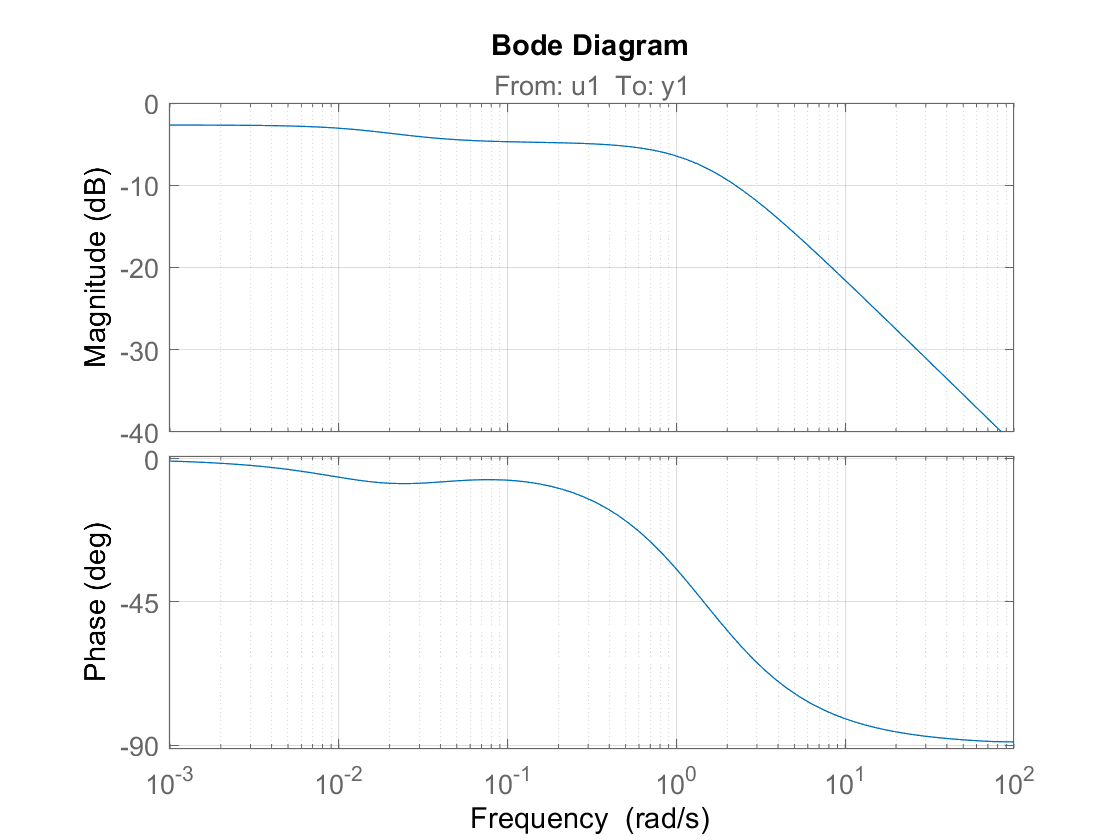


bode(sys)
grid on

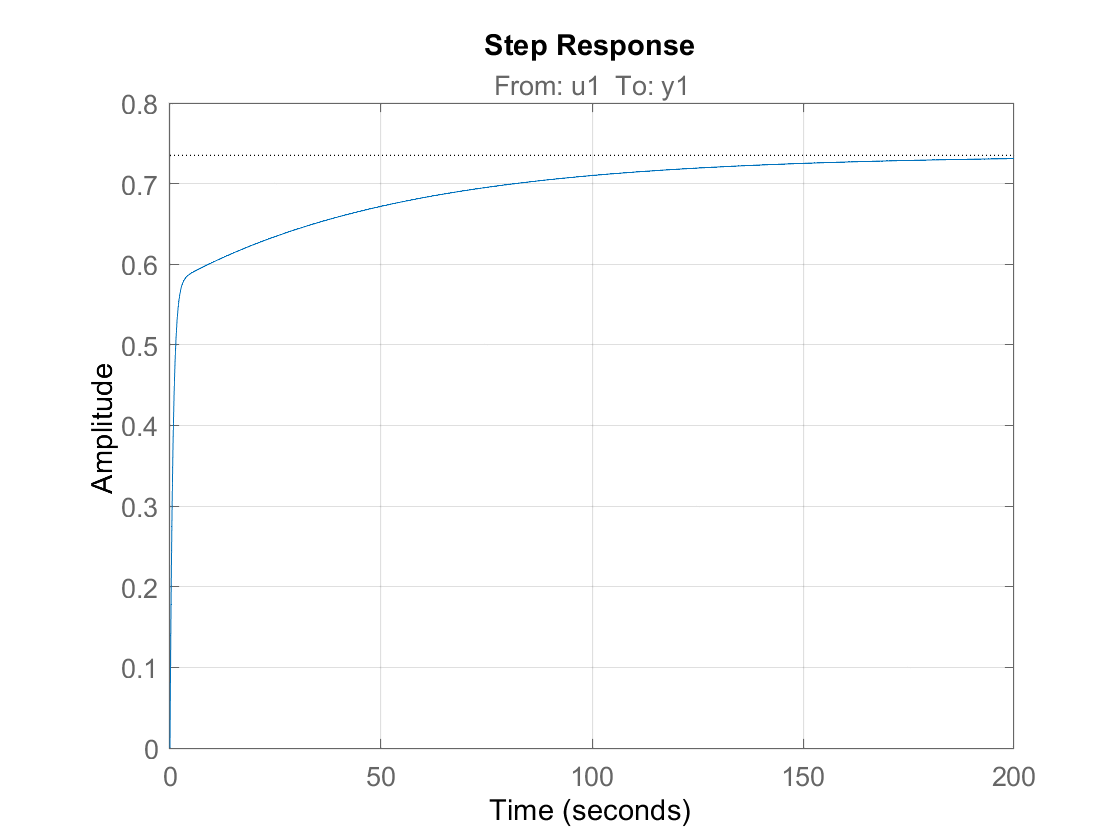

step(sys)
grid on

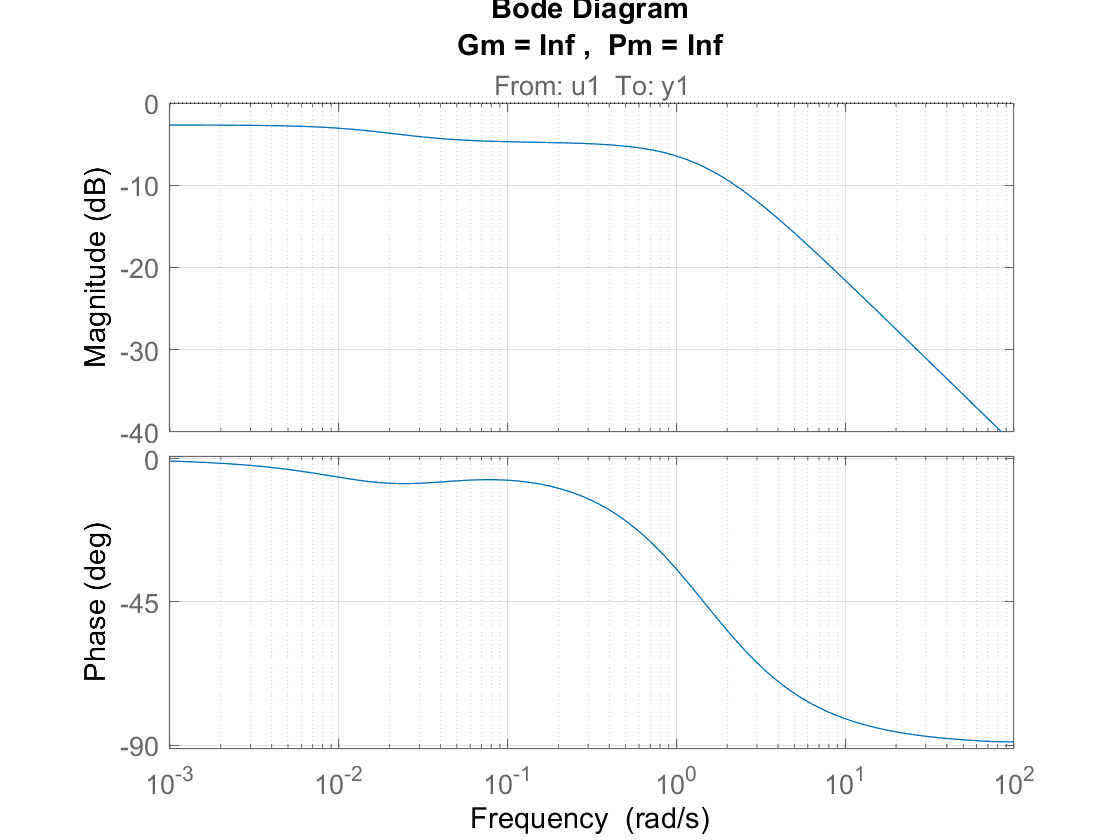


margin(sys)
grid on


G = sys;







input_angle = angle_input.Data

input_angle =     0.2873
    0.9293
   -0.0966
    0.5810
    0.2366
    0.0519
   -0.1163
    0.2181
    0.3570
    0.2543


output_angle = angle_vel_r_output.Data

output_angle =          0
    0.0079
    0.0157
    0.0233
    0.0307
    0.0379
    0.0467
    0.0552
    0.0636
    0.0717





count=1;
output_angle_vel_r_updated = zeros(length(input_angle),1);

% uses modulus 
for i = 1:length(output_angle) 
   if mod(i,5) == 0
       output_angle_vel_r_updated(count) = output_angle(i);
       count = count+1;
   end
end
output_angle_r_updated(length(input_angle)) = output_angle(length(output_angle));

% updated output
output_angle_vel_r_updated

output_angle_vel_r_updated =     0.0307
    0.0717
    0.0622
    0.0899
    0.1133
    0.1112
    0.0872
    0.0976
    0.1284
    0.1482




%tf = tfestimate(input_u,output_u_updated)

%bode(tf)

%tf = tfestimate(vel_u_input,vel_u_output)



output_angle_vel_r_updated = output_angle_vel_r_updated(1001:2001)

output_angle_vel_r_updated =     0.1304
    0.1154
    0.0913
    0.0773
    0.0991
    0.1315
    0.1349
    0.1462
    0.1359
    0.1285


input_angle = input_angle(1001:2001)

input_angle =     0.3550
   -0.0731
   -0.0829
   -0.0155
    0.2904
    0.4137
    0.1033
    0.2396
    0.0188
    0.0822




% create iddata object by specifying output signal, input signal, and sampling time
sample_time = 0.1;
%data=iddata(output_u_updated,input_u);
data=iddata(output_angle_vel_r_updated,input_angle,sample_time);
% estimate a transfer function with 2 poles and 1 zero
%sys=tfest(data,1,0)
sys=tfest(data,1,1)

sys =
 
  From input "u1" to output "y1":
  0.07339 s + 0.93
  ----------------
      s + 1.28
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 1   Number of zeros: 1
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: 66.44%                   
FPE: 0.0003446, MSE: 0.0003419                   




poles_sys = pole(sys)

poles_sys = -1.2796

zeros_sys = zero(sys)

zeros_sys = -12.6716

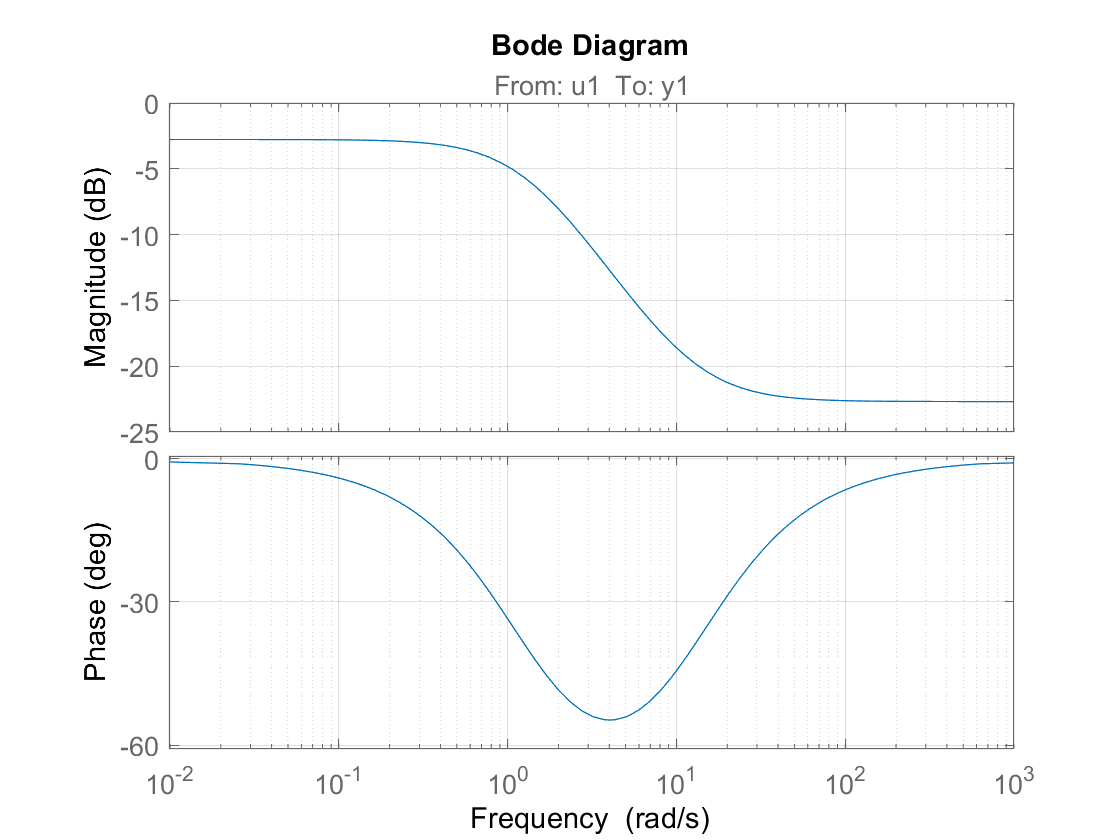


bode(sys)
grid on

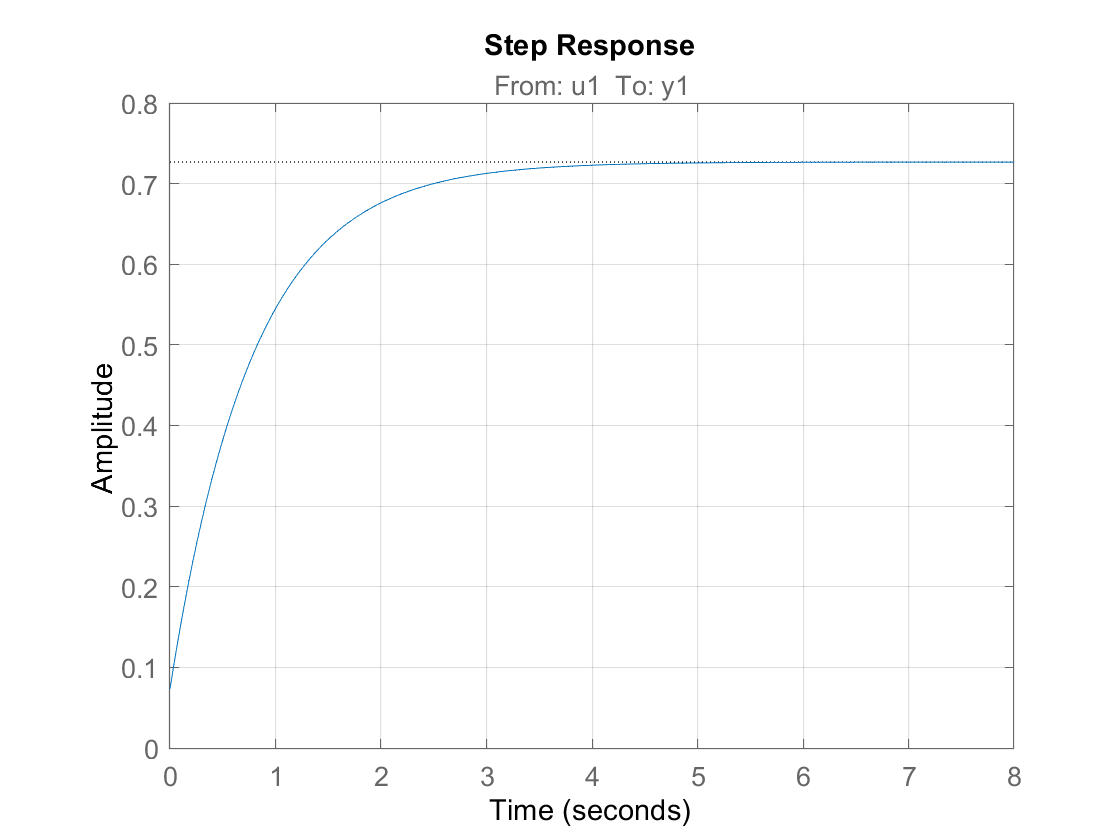

step(sys)
grid on

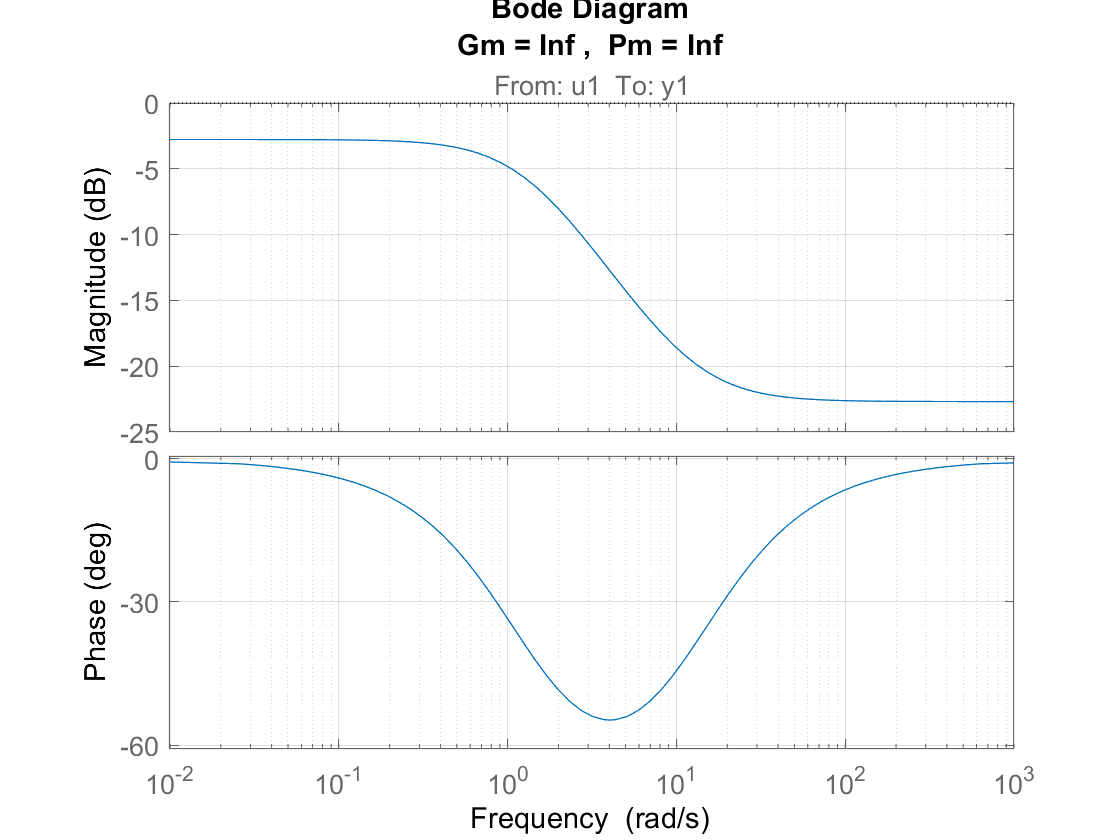


margin(sys)
grid on


G = sys;




## P- regulator


dbmag= 6


Kp = 10^(dbmag/20) %ca -17 aflæses fra bode plottet ved -180+fasemargin(60)
%så ved -120. samme frekvens findes i magnitude plottet, og dB aflæses 
%disp(Kp);

Gol_P = Kp*G
bode(Gol_P)
grid on
step(Gol_P)
grid on

poles_P = pole(Gol_P)
zeros_P = zero(Gol_P)



## med lukket sløjfe

%Kp_up = Kp * 25
Kp_up = Kp * 2
%Kp_up = 2
G_up = minreal(Kp_up*G/(1+G*Kp_up),1.0e-5)
step(G_up)



## PI regulator

## PI ud fra phasen

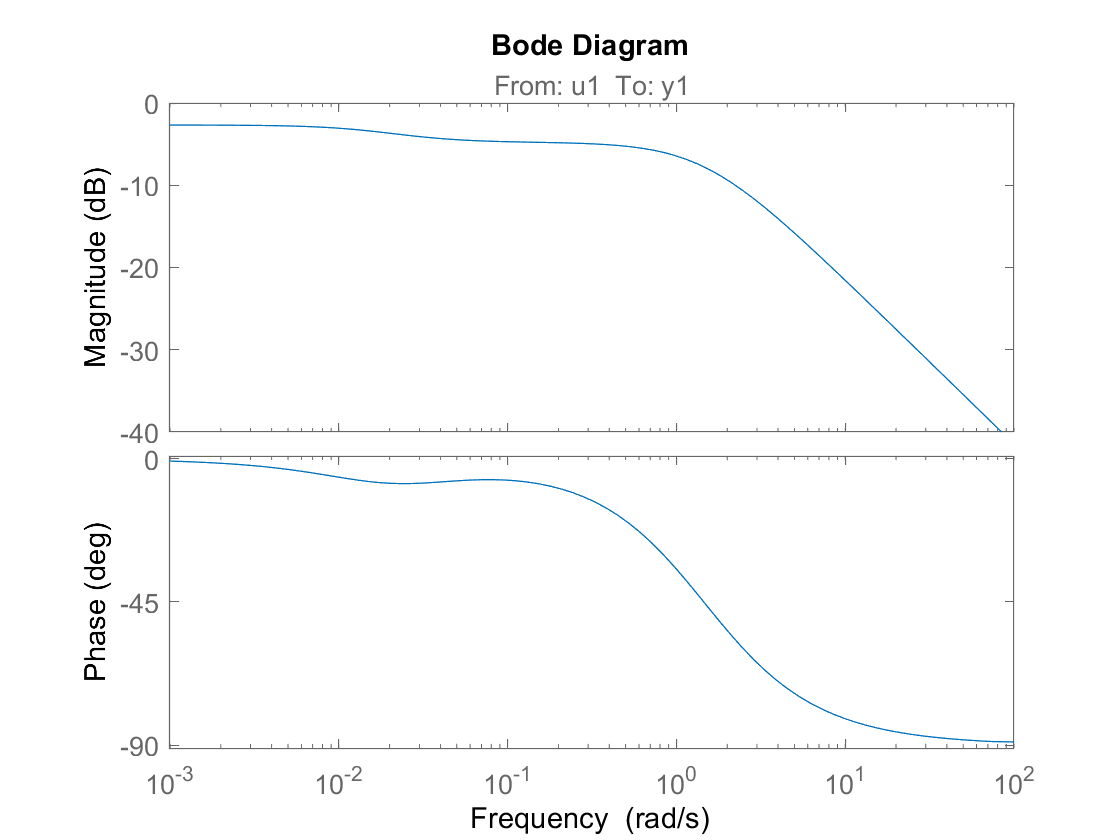


%vælger fasen ved -60 grader -> vi ligger nulpunktet i i-ledet 5-10 gange
%lavere end fasemargin frekvensen for en p-kontroller 
% sørg for at den endelige phasemargin er under 180- meget vigtigt, men det
% er på den endelige bode

bode(G)


% sim er 50Hz så båndbredden skal være omkring 10 gange lavere  

omega_c = 2;
tau_i = 6* 1/omega_c

tau_i = 3

%tau_i = 2*0.3

% Controller transfer
Ci = tf([tau_i 1],[tau_i 0]);     % I and PI zero
Gol_PI = Ci*G                    % open loop

Gol_PI =
 
  From input "u1" to output:
  2.533 s^2 + 0.9043 s + 0.02001
  ------------------------------
   3 s^3 + 4.445 s^2 + 0.0817 s
 
Continuous-time transfer function.



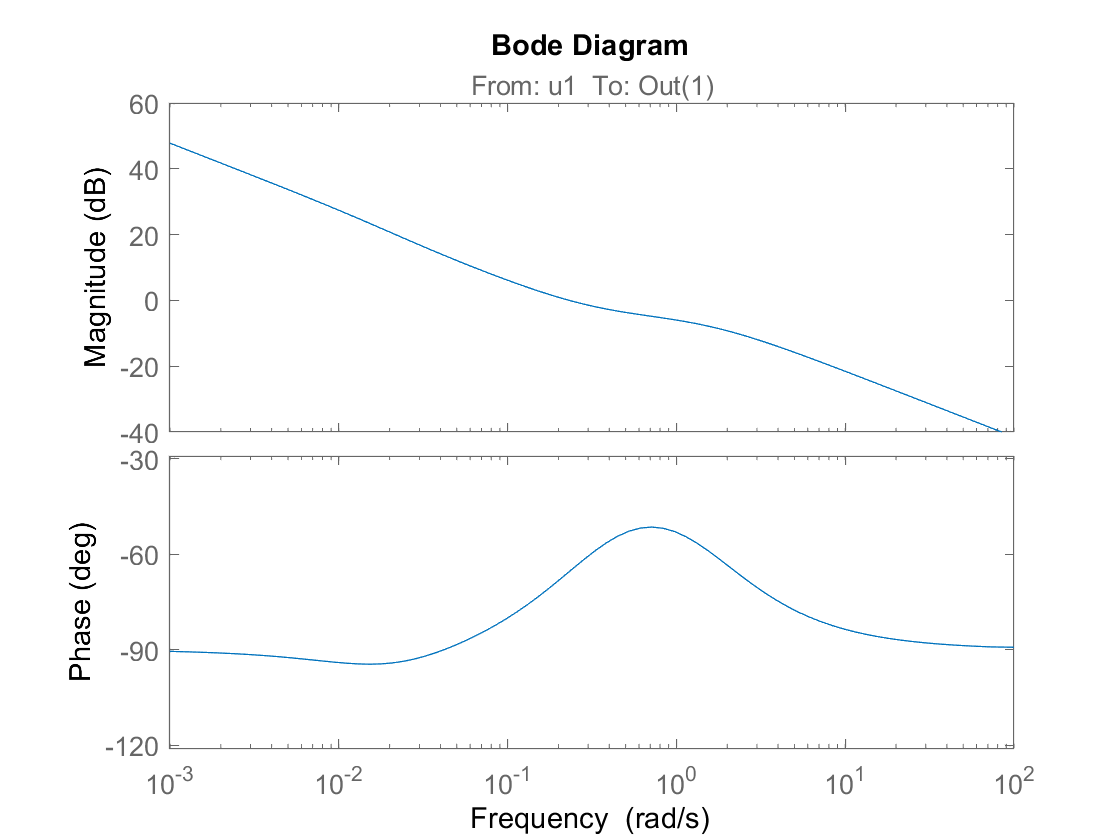


bode(Gol_PI)



dbmag = 7.6 % rykker den en smule mere op i frekvens (er stadig under 180)

dbmag = 7.6000

dbmag = 3.60

dbmag = 3.6000

%dbmag = 5

Kp = 10^(dbmag/20) %ca -17 aflæses fra bode plottet ved -180+fasemargin(60)

Kp = 1.5136

%så ved -120. samme frekvens findes i magnitude plottet, og dB aflæses 
%disp(Kp);
%Kp = 2
Gol_PI_r = Kp*Ci*G                    % open loop

Gol_PI_r =
 
  From input "u1" to output:
  3.834 s^2 + 1.369 s + 0.03029
  -----------------------------
  3 s^3 + 4.445 s^2 + 0.0817 s
 
Continuous-time transfer function.



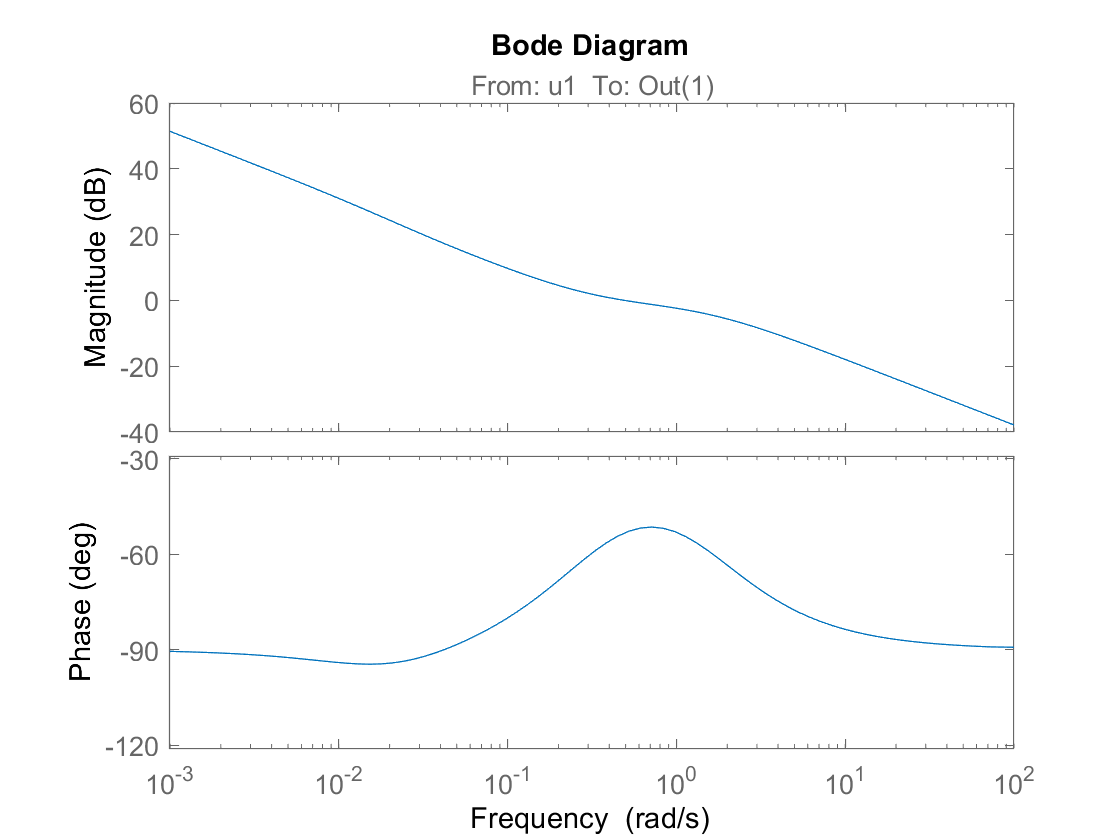


bode(Gol_PI_r)


G_close = minreal(Gol_PI_r/(1+Gol_PI_r),0.1e-5)

G_close =
 
    1.278 s^2 + 0.4563 s + 0.0101
  ----------------------------------
  s^3 + 2.76 s^2 + 0.4835 s + 0.0101
 
Continuous-time transfer function.



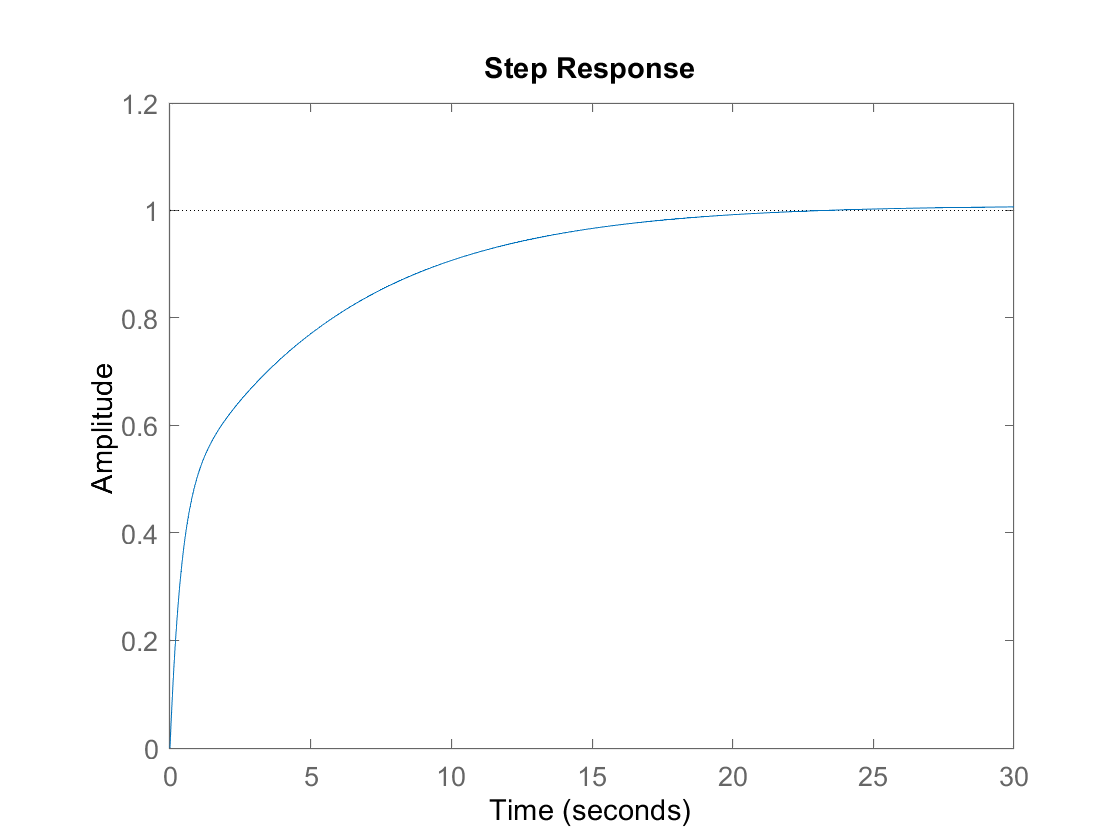

step(G_close)

## PI regulator

## PI ud fra phasen

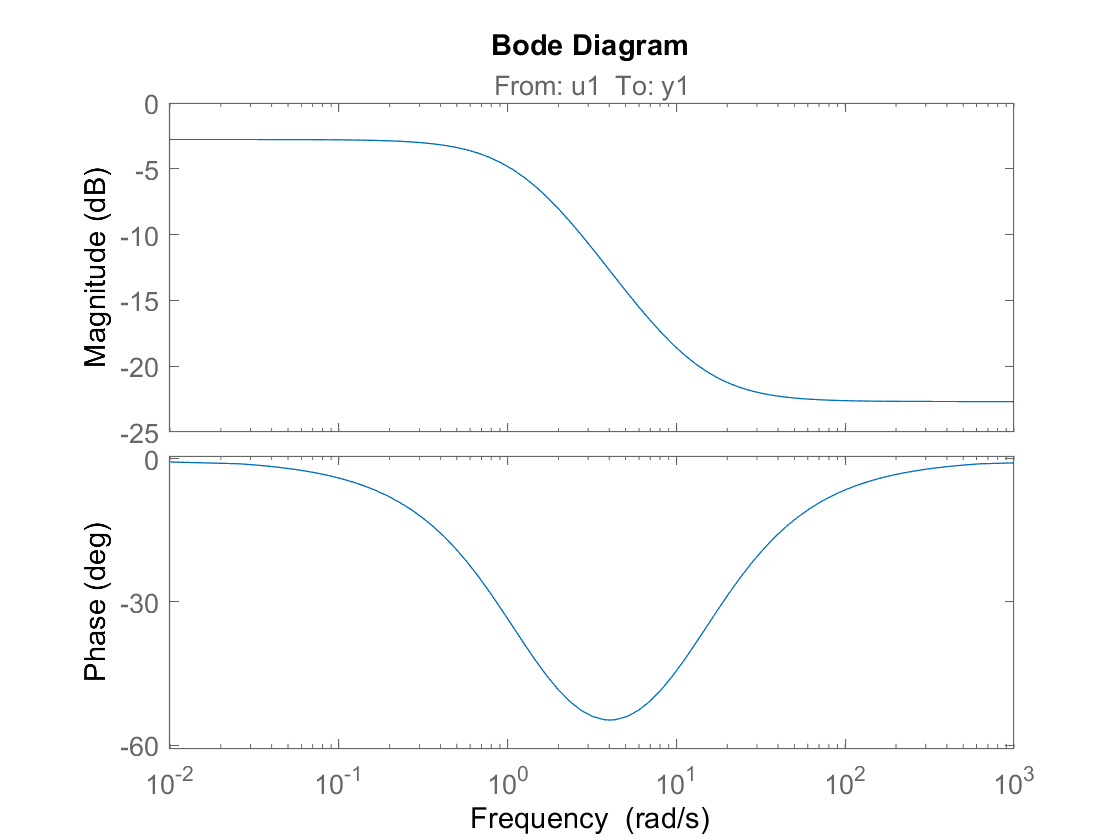


%vælger fasen ved -60 grader -> vi ligger nulpunktet i i-ledet 5-10 gange
%lavere end fasemargin frekvensen for en p-kontroller 
% sørg for at den endelige phasemargin er under 180- meget vigtigt, men det
% er på den endelige bode

bode(G)


% sim er 50Hz så båndbredden skal være omkring 10 gange lavere  

omega_c = 2;
tau_i = 1/omega_c

tau_i = 0.5000

%tau_i = 2*0.3

% Controller transfer
Ci = tf([tau_i 1],[tau_i 0]);     % I and PI zero
Gol_PI = Ci*G                    % open loop

Gol_PI =
 
  From input "u1" to output:
  0.0367 s^2 + 0.5384 s + 0.93
  ----------------------------
       0.5 s^2 + 0.6398 s
 
Continuous-time transfer function.



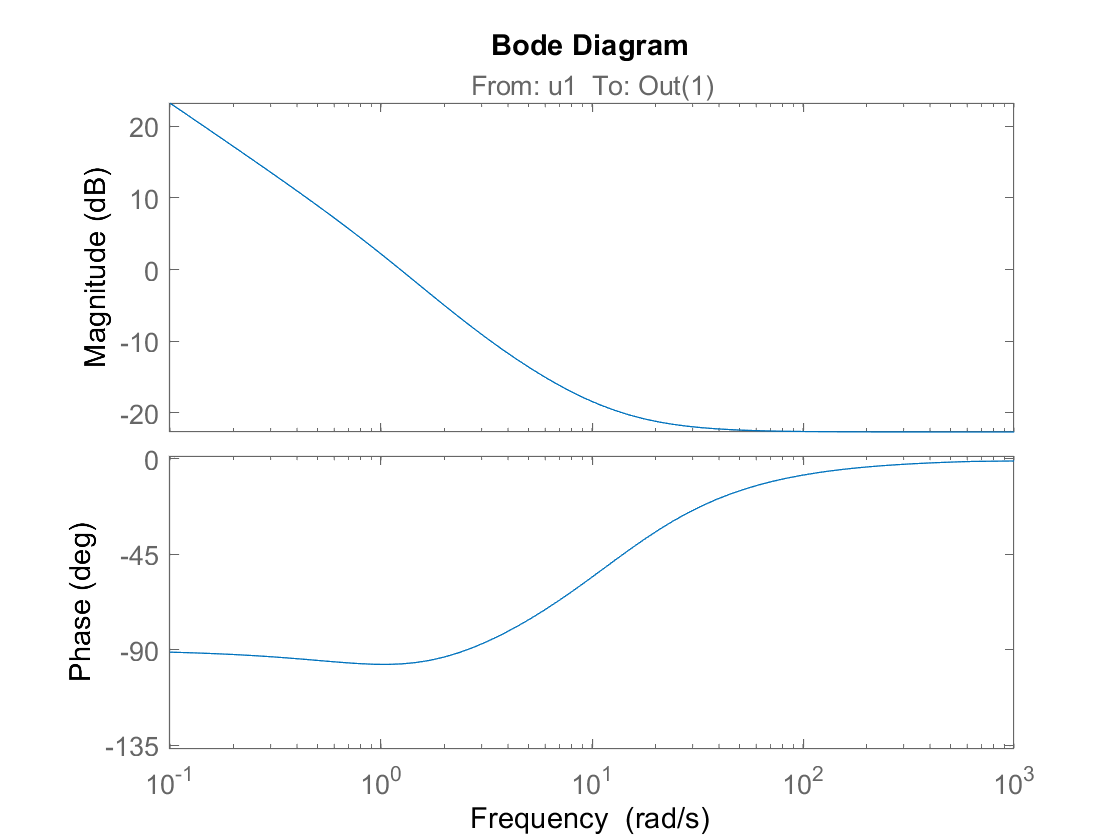


bode(Gol_PI)



dbmag = 7.6 % rykker den en smule mere op i frekvens (er stadig under 180)

dbmag = 7.6000

dbmag = 1.5836

dbmag = 1.5836

%dbmag = 5

Kp = 10^(dbmag/20) %ca -17 aflæses fra bode plottet ved -180+fasemargin(60)

Kp = 1.2000

%så ved -120. samme frekvens findes i magnitude plottet, og dB aflæses 
%disp(Kp);
%Kp = 2
Gol_PI_r = Kp*Ci*G                    % open loop

Gol_PI_r =
 
  From input "u1" to output:
  0.04403 s^2 + 0.646 s + 1.116
  -----------------------------
       0.5 s^2 + 0.6398 s
 
Continuous-time transfer function.



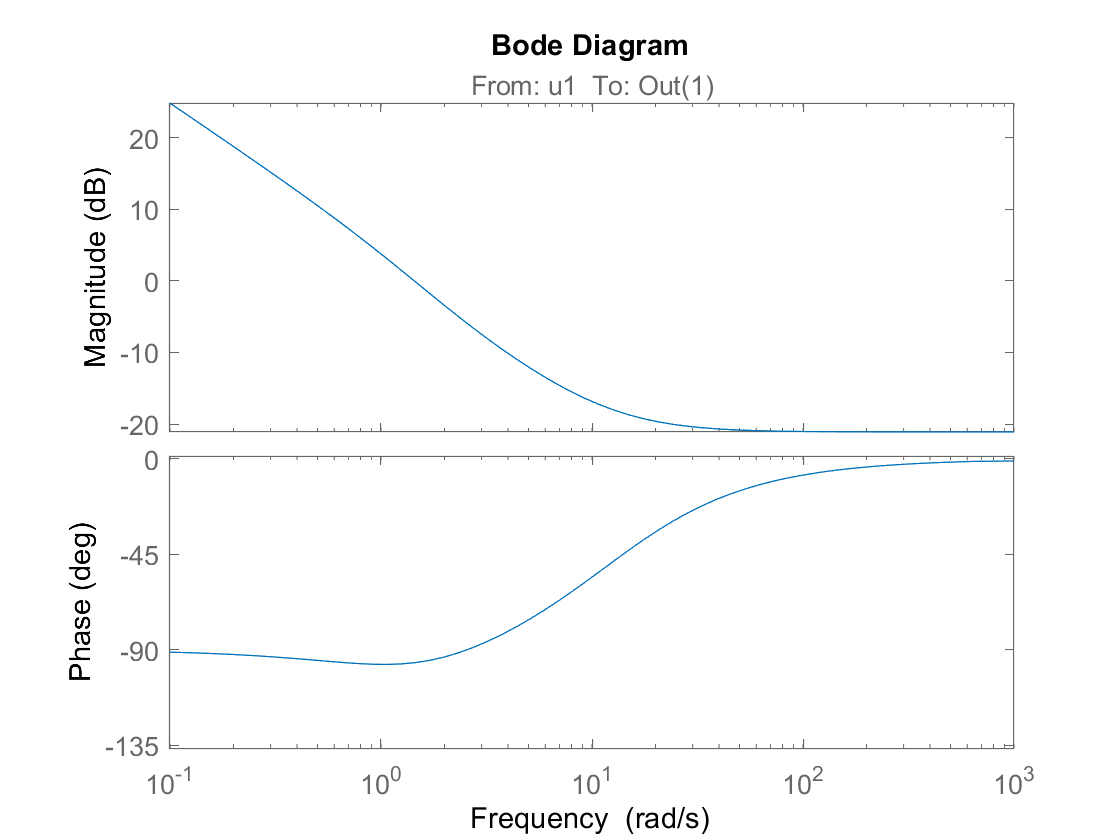


bode(Gol_PI_r)


G_close = minreal(Gol_PI_r/(1+Gol_PI_r),0.1e-5)

G_close =
 
  0.08094 s^2 + 1.188 s + 2.051
  -----------------------------
      s^2 + 2.364 s + 2.051
 
Continuous-time transfer function.



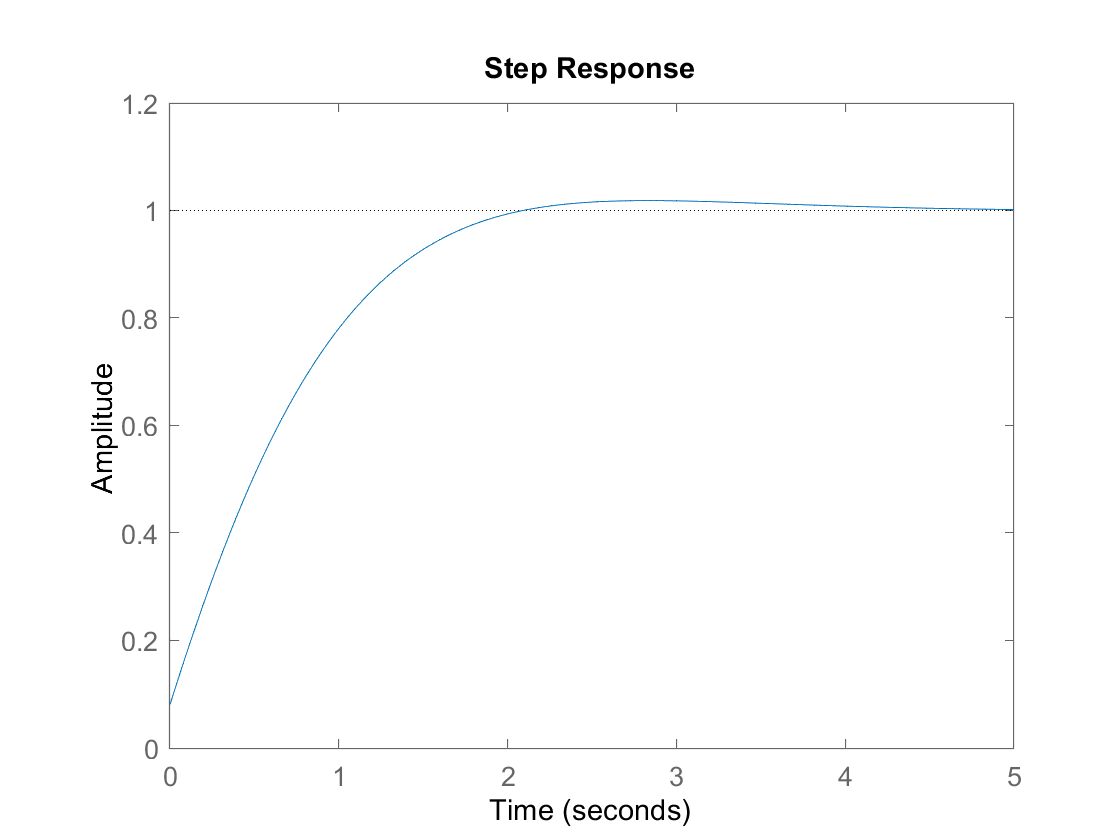

step(G_close)


Ni       =  1.2;
gamma_m  = 60; % fasemargin


phi_PI   = -90 + atan(Ni)*180/pi;
arg      = -180 + gamma_m - phi_PI

% aflæs i phase plot på phase(arg) 
omega_c  = 9

tau_i = Ni/omega_c


%hvor meget ønsker vi at løfte eller sænke? (+ for løfte, - for sænke)sæt
%ind her ved dbmag
dbmag=72
Kp = 10^(dbmag/20)



% Controller transfer
Ci = tf([tau_i 1],[tau_i 0]);     % I and PI zero
Gol_PI = Kp*Ci*G                     % open loop

bode(Gol_PI)
grid on 
poles_PI = pole(Gol_PI)
zeros_PI = zero(Gol_PI)
step(Gol_PI)
grid on

## Design af PID

Ni       = 3 ;% (100/80);
alpha    = 0.2;
gamma_m  = 60; % fasemargin

phi_lead = asin((1-alpha)/(1+alpha))*180/pi;
phi_PI   = -90 + atan(Ni)*180/pi;
arg      = -180 + gamma_m -phi_lead - phi_PI

% aflæs i phase plot på phase(arg) 
omega_c  = 0.00077337;
omega_c  = 0.3;
%omega_c  = 1;

tau_i    = Ni/omega_c
tau_d    = 1/(omega_c*sqrt(alpha))


%hvor meget ønsker vi at løfte eller sænke? (+ for løfte, - for sænke)
dbmag=-0.2178
%dbmag=+18
%dbmag=+0.00001;
Kp = 10^(dbmag/20)


% Controller transfer
Ci = tf([tau_i 1],[tau_i 0]);         % I and PI zero
Cd = tf([tau_d 1],[alpha*tau_d 1]);   % lead
Gol_PID = Kp*Ci*Cd*G                     % open loop


bode(Gol_PID)
grid on 
poles_PID = pole(Gol_PID)
zeros_PID = zero(Gol_PID)
step(Gol_PID)


## PD

alpha    = 2;
gamma_m  = 60; % fasemargin

phi_lead = asin((1-alpha)/(1+alpha))*180/pi;
arg      = -180 + gamma_m -phi_lead - phi_PI

% aflæs i phase plot på phase(arg) 
omega_c  = 0.077337;
%omega_c  = 1;

tau_d    = 1/(omega_c*sqrt(alpha))

%hvor meget ønsker vi at løfte eller sænke? (+ for løfte, - for sænke)
dbmag = 0.55
Kp = 10^(dbmag/20)


% Controller transfer
Cd = tf([tau_d 1],[alpha*tau_d 1]);   % lead
Gol_PD = Kp*Cd*G                      % open loop


bode(Gol_PD)
grid on 
poles_PD = pole(Gol_PD)
zeros_PD = zero(Gol_PD)
step(Gol_PD)



## psi Yaw

## Transfer function for black box

(90 degrees (pi/2))

% loader modellen 
Sim_Time = 200;

model = "sys_PID"

model = "sys_PID"

Found algebraic loop containing: 
sys_PID/controllers/PIDs/PID Surge/Saturation2 (discontinuity)
sys_PID/controllers/PIDs/PID Surge/Sum (algebraic variable)
sys_PID/controllers/PIDs/PID Surge/Gain
sys_PID/controllers/PIDs/PID Surge/Sum3
sys_PID/controllers/PIDs/PID Surge/Sum5 (algebraic variable)


KKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKK


alpha_1 = 
    3.1416



ans =
alpha =      8

    3.1416

ans =
F1 =      5

 -295.6000

ALPHA_FLAG =
     0



KKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKK
alpha_1 = 
    3.1416

ans =
alpha =      8

    3.1416

ans =
F1 =      5

 -295.6000

ALPHA_FLAG =
     0

KKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKK
alpha_1 = 
    3.1416

ans =
alpha =      8

    3.1416

ans =
F1 =      5

 -295.6000

ALPHA_FLAG =
     0

KKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKK
alpha_1 = 
    3.1416

ans =
alpha =      8

    3.1416

ans =
F1 =      5

 -295.6000

ALPHA_FLAG =
     0

KKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKK
alpha_1 = 
    3.1416

ans =
alpha =      8

    3.1416

ans =
F1 =      5

 -295.6000

ALPHA_FLAG =
     0

KKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKKK
alpha_1 = 
    3.1416

ans =
alpha =      8

    3.1416

ans =
F1 =      5

 -295.6000

ALPHA_FLAG =
     0



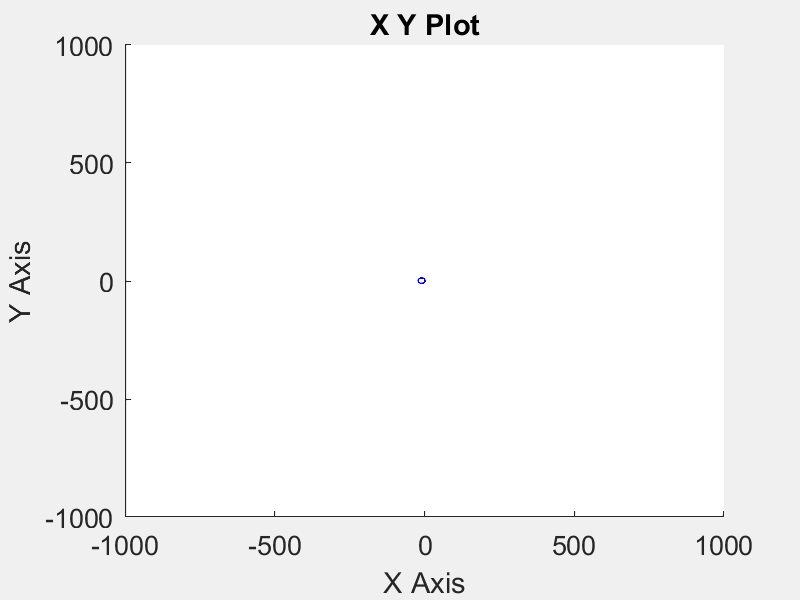

load_system(model);
open_system(model);

sim(model,Sim_Time)

input_yaw = input_r_controller.Data

input_yaw =     0.7411
    1.3830
    0.3572
    1.0348
    0.6904
    0.5057
    0.3375
    0.6719
    0.8108
    0.7080


output_yaw = yaw_output.Data

output_yaw =          0
         0
    0.0001
    0.0004
    0.0007
    0.0012
    0.0018
    0.0025
    0.0033
    0.0043





count=1;
output_yaw_updated = zeros(length(input_yaw),1);

% uses modulus 
for i = 1:length(output_yaw) 
   if mod(i,5) == 0
       output_yaw_updated(count) = output_yaw(i);
       count = count+1;
   end
end
output_yaw_updated(length(input_yaw)) = output_yaw(length(output_yaw));

% updated output
output_yaw_updated

output_yaw_updated =     0.0007
    0.0043
    0.0104
    0.0188
    0.0292
    0.0413
    0.0549
    0.0697
    0.0856
    0.1025




%tf = tfestimate(input_u,output_u_updated)

%bode(tf)

%tf = tfestimate(vel_u_input,vel_u_output)



output_yaw_updated = output_yaw_updated(1001:2001)

output_yaw_updated =    17.1430
   17.1601
   17.1775
   17.1950
   17.2128
   17.2306
   17.2486
   17.2667
   17.2848
   17.3029


input_yaw = input_yaw(1001:2001)

input_yaw =     0.8087
    0.3807
    0.3709
    0.4383
    0.7442
    0.8675
    0.5571
    0.6933
    0.4726
    0.5359




% create iddata object by specifying output signal, input signal, and sampling time
sample_time = 0.1;
%data=iddata(output_u_updated,input_u);
data=iddata(output_yaw_updated,input_yaw,sample_time);
% estimate a transfer function with 2 poles and 1 zero
sys=tfest(data,1,1)

sys =
 
  From input "u1" to output "y1":
  0.01103 s + 0.2808
  ------------------
    s + 0.0003244
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 1   Number of zeros: 1
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: 99.22%                   
FPE: 0.001476, MSE: 0.001464                     


%sys=tfest(data,1,1)

poles_sys = pole(sys)

poles_sys = -3.2442e-04

zeros_sys = zero(sys)

zeros_sys = -25.4554

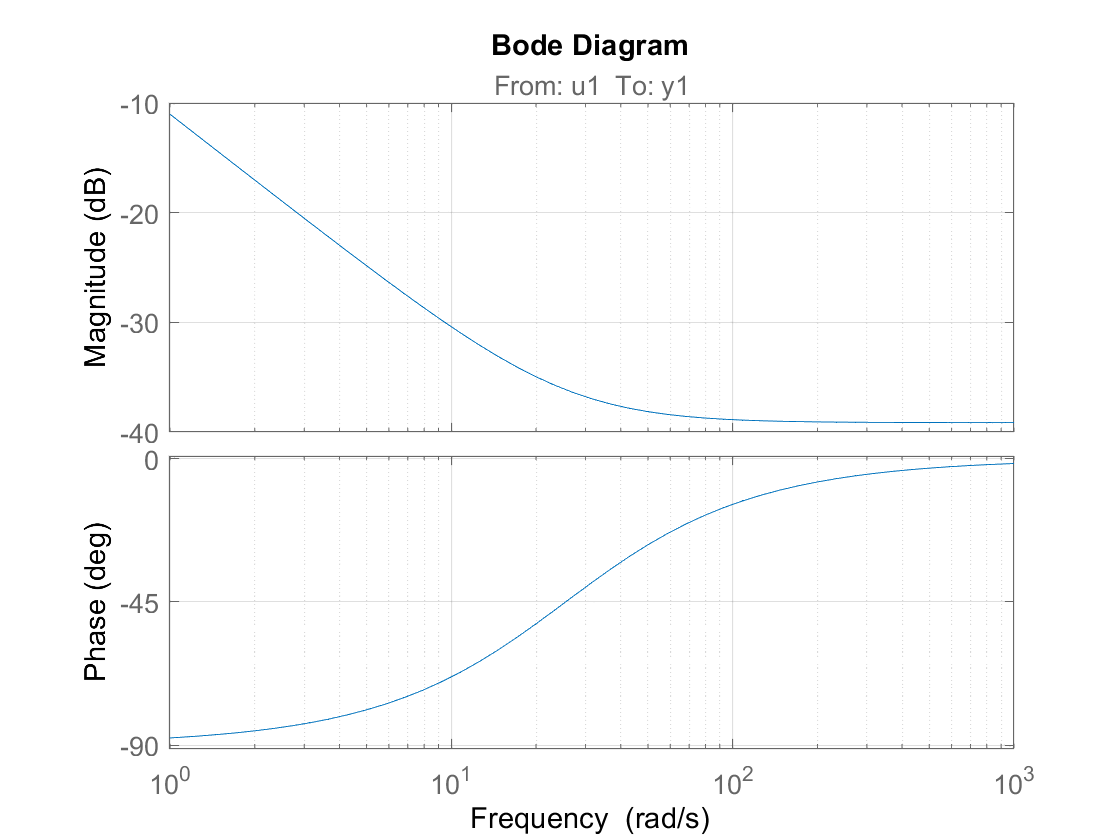


bode(sys)
grid on

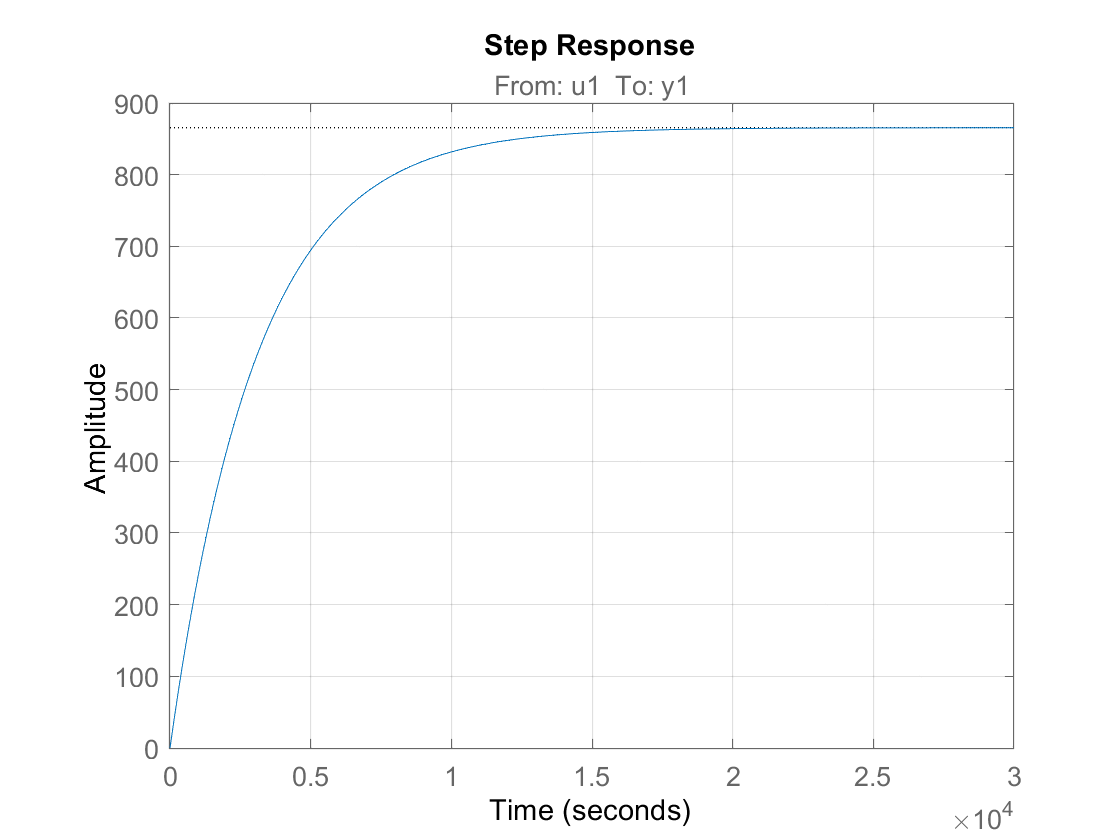

step(sys)
grid on

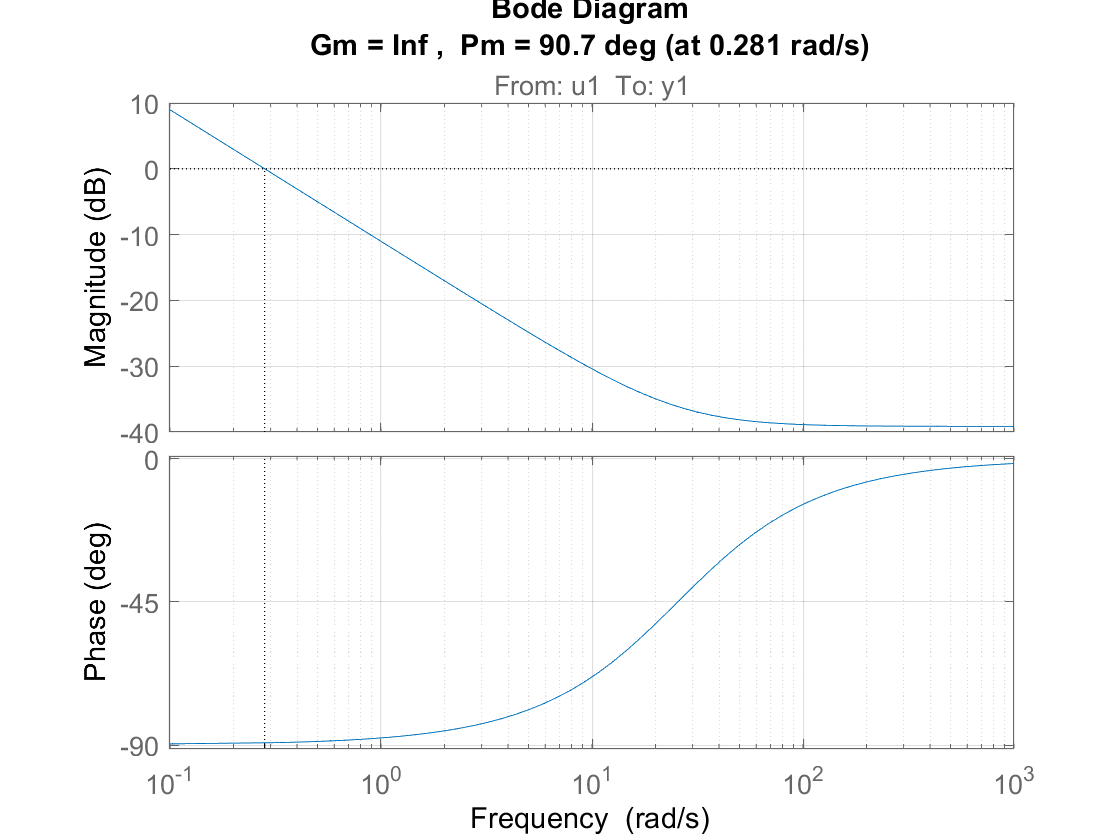


margin(sys)
grid on


G = sys;


## P- regulator

dbmag= 5

dbmag = 5

%dbmag= -20

Kp = 10^(dbmag/20) 

Kp = 1.7783


Gol_P = Kp*G

Gol_P =
 
  From input "u1" to output:
  0.01962 s + 0.4993
  ------------------
    s + 0.0003244
 
Continuous-time transfer function.



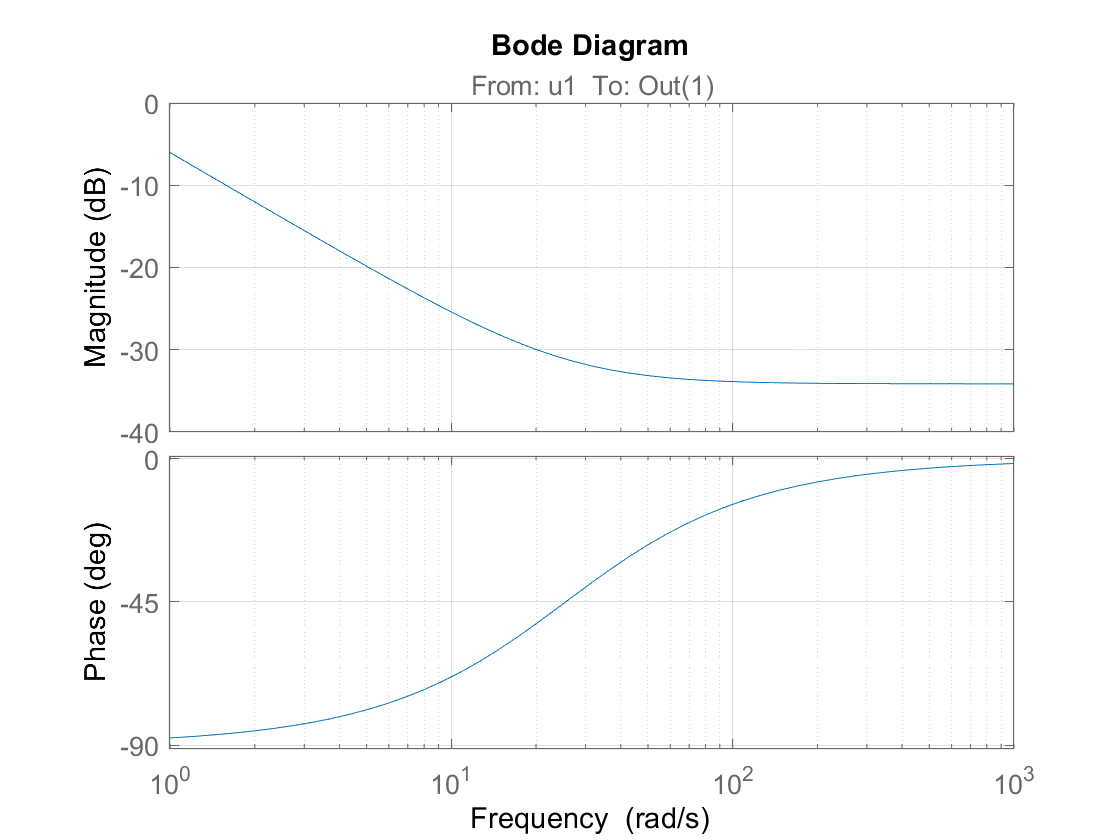

bode(Gol_P)
grid on

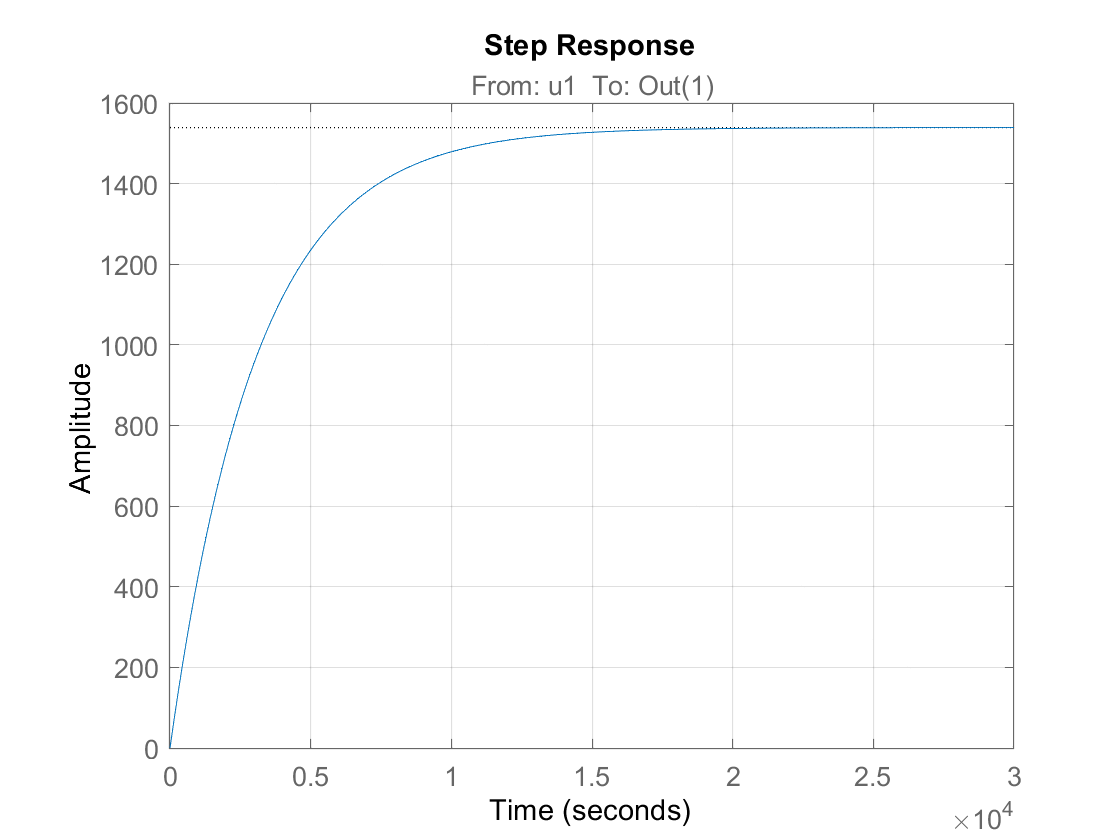

step(Gol_P)
grid on


poles_P = pole(Gol_P)

poles_P = -3.2442e-04

zeros_P = zero(Gol_P)

zeros_P = -25.4554

## med lukket sløjfe


Kp_up = Kp %* 25

Kp_up = 1.7783

G_up = minreal(G/(1+G*Kp_up),1.0e-5)

G_up =
 
  From input "y1" to output "y1":
  0.01082 s + 0.2754
  ------------------
       s + 0.49
 
Continuous-time transfer function.



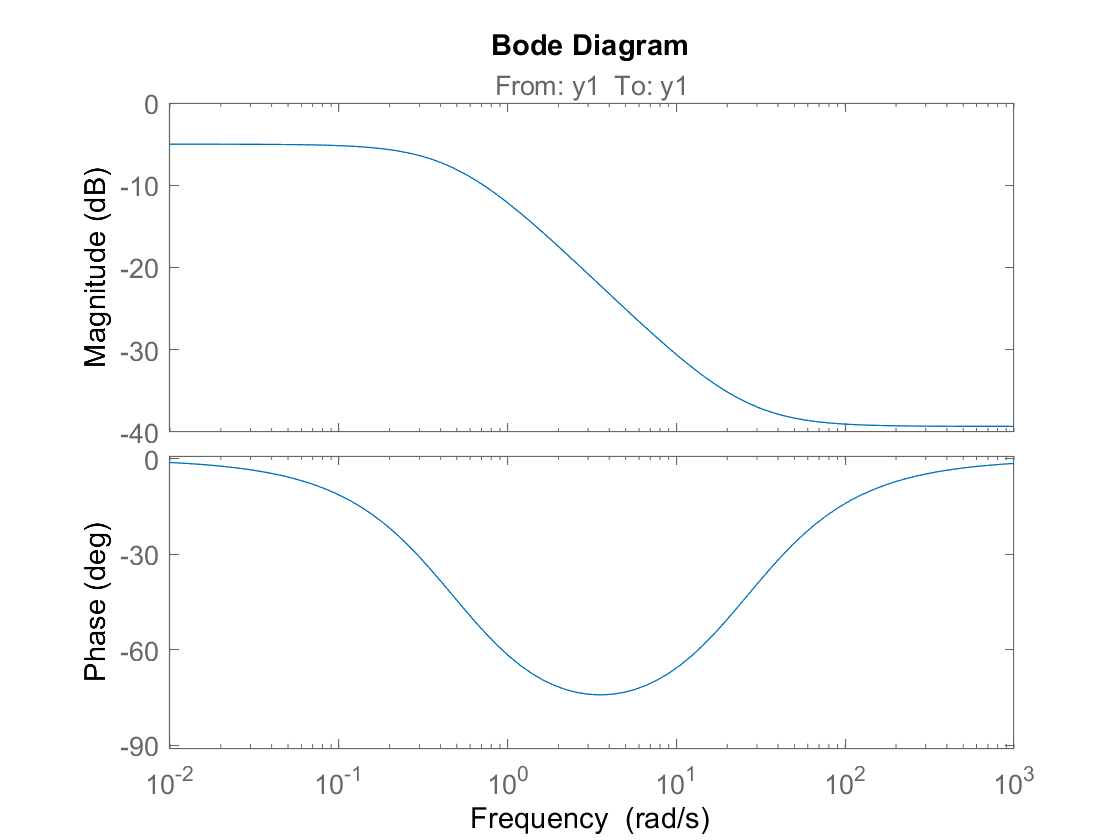

bode(G_up)

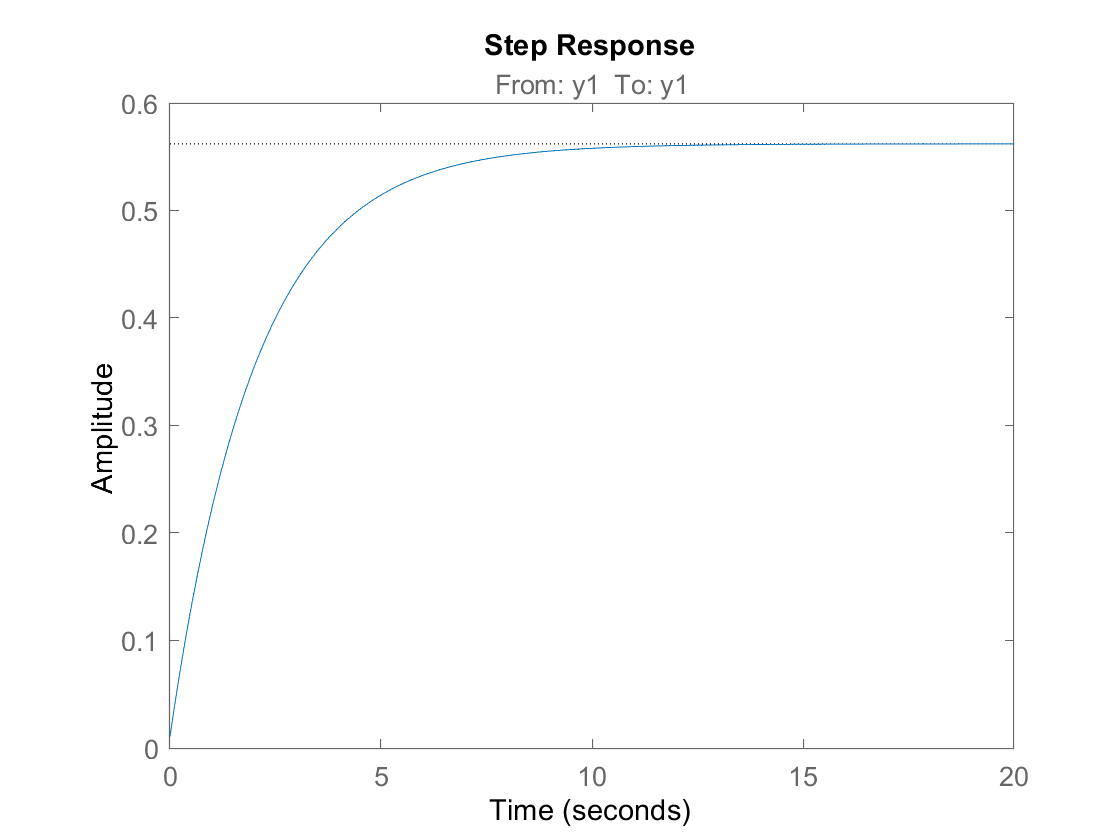

step(G_up)


%Kp_up = Kp * 25
Kp_up = Kp 

Kp_up = 1.7783

Kp_up = 0.98

Kp_up = 0.9800

G_up = minreal(Kp_up*G/(1+G*Kp_up),1.0e-5)

G_up =
 
  From input "y1" to output:
  0.01069 s + 0.2722
  ------------------
      s + 0.2726
 
Continuous-time transfer function.



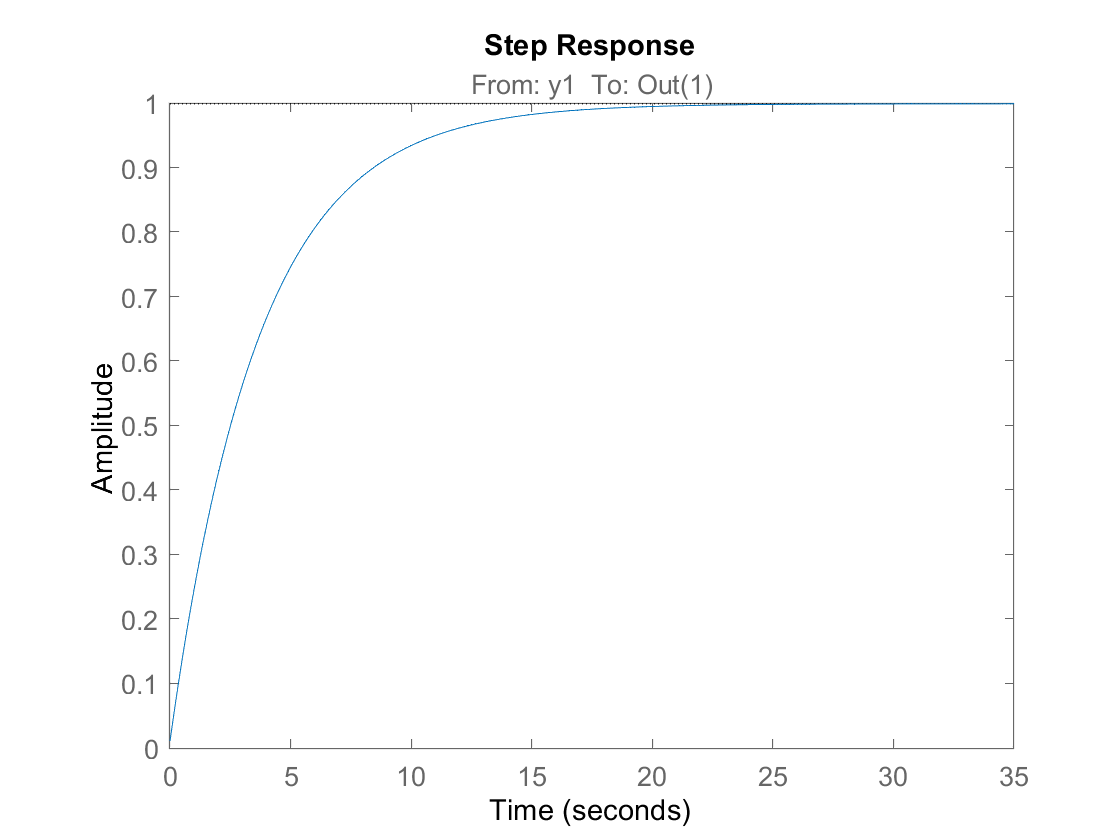

step(G_up)

## PI regulator

## Ud fra phase


%vælger fasen ved -60 grader -> vi ligger nulpunktet i i-ledet 5-10 gange
%lavere end fasemargin frekvensen for en p-kontroller 
% sørg for at den endelige phasemargin er under 180- meget vigtigt, men det
% er på den endelige bode

bode(G)

% sim er 50Hz så båndbredden skal være omkring 10 gange lavere  

omega_c = 3;
tau_i = 1/omega_c


% Controller transfer
Ci = tf([tau_i 1],[tau_i 0]);     % I and PI zero
Gol_PI = Ci*G                    % open loop

bode(Gol_PI)


dbmag = 7.6 % rykker den en smule mere op i frekvens (er stadig under 180)
%dbmag = 22

Kp = 10^(dbmag/20) %ca -17 aflæses fra bode plottet ved -180+fasemargin(60)
%så ved -120. samme frekvens findes i magnitude plottet, og dB aflæses 
%disp(Kp);
Kp = 2
Gol_PI_r = Kp*Ci*G                    % open loop

bode(Gol_PI_r)

G_close = minreal(Gol_PI_r/(1+Gol_PI_r),0.1e-5)
step(G_close)



Ni       =  3;
gamma_m  = 60; % fasemargin


phi_PI   = -90 + atan(Ni)*180/pi;
arg      = -180 + gamma_m - phi_PI

% aflæs i phase plot på phase(arg) 
omega_c  = 0.2073

tau_i = Ni/omega_c


%hvor meget ønsker vi at løfte eller sænke? (+ for løfte, - for sænke)sæt
%ind her ved dbmag
dbmag=61.47
Kp = 10^(dbmag/20)



% Controller transfer
Ci = tf([tau_i 1],[tau_i 0]);     % I and PI zero
Gol_PI = Kp*Ci*G                     % open loop

bode(Gol_PI)
grid on 
poles_PI = pole(Gol_PI)
zeros_PI = zero(Gol_PI)
step(Gol_PI)
grid on

## Design af PID

## PID ud fra phasen

%vælger fasen ved -60 grader -> vi ligger nulpunktet i i-ledet 5-10 gange
%lavere end fasemargin frekvensen for en p-kontroller 
% sørg for at den endelige phasemargin er under 180- meget vigtigt, men det
% er på den endelige bode

alpha = 0.002;


bode(G)

% sim er 50Hz så båndbredden skal være omkring 10 gange lavere  

omega_c = 3;
tau_i = 1/omega_c;

tau_d = 1/(omega_c*sqrt(alpha));

% Controller transfer
Ci = tf([tau_i 1],[tau_i 0]);         % I and PI zero
Cd = tf([tau_d 1],[alpha*tau_d 1]);   % lead
Gol_PID_phase = Ci*Cd*G                      % open loop

bode(Gol_PID_phase)



dbmag = -19.444 % rykker den en smule mere op i frekvens (er stadig under 180)
dbmag = -1

Kp = 10^(dbmag/20) %ca -17 aflæses fra bode plottet ved -180+fasemargin(60)
%så ved -120. samme frekvens findes i magnitude plottet, og dB aflæses 
%disp(Kp);

Gol_PID_p = Kp*Cd*Ci*G                    % open loop

bode(Gol_PID_p)

G_close = minreal(Gol_PID_p/(1+Gol_PID_p),0.1e-5)
step(G_close)

## bog_metode


Ni       = 3 ;% (100/80);
alpha    = 0.2;
gamma_m  = 60; % fasemargin

phi_lead = asin((1-alpha)/(1+alpha))*180/pi;
phi_PI   = -90 + atan(Ni)*180/pi;
arg      = -180 + gamma_m -phi_lead - phi_PI

% aflæs i phase plot på phase(arg) 
omega_c  = 0.077337;
%omega_c  = 1;

tau_i    = Ni/omega_c
tau_d    = 1/(omega_c*sqrt(alpha))


%hvor meget ønsker vi at løfte eller sænke? (+ for løfte, - for sænke)
dbmag=-0.2178
%dbmag=+18
%dbmag=+0.00001;
Kp = 10^(dbmag/20)


% Controller transfer
Ci = tf([tau_i 1],[tau_i 0]);         % I and PI zero
Cd = tf([tau_d 1],[alpha*tau_d 1]);   % lead
Gol_PID = Kp*Ci*Cd*G                     % open loop


bode(Gol_PID)
grid on 
poles_PID = pole(Gol_PID)
zeros_PID = zero(Gol_PID)
step(Gol_PID)


## PD

## PD ud fra phasen

%vælger fasen ved -60 grader -> vi ligger nulpunktet i i-ledet 5-10 gange
%lavere end fasemargin frekvensen for en p-kontroller 
% sørg for at den endelige phasemargin er under 180- meget vigtigt, men det
% er på den endelige bode

alpha = 0.35;


bode(G)

% sim er 50Hz så båndbredden skal være omkring 10 gange lavere  

omega_c = 3;


tau_d = 1/(omega_c*sqrt(alpha));

% Controller transfer
Cd = tf([tau_d 1],[alpha*tau_d 1]);   % lead
Gol_PD_phase = Ci*Cd*G                      % open loop

bode(Gol_PD_phase)



dbmag = 5 % rykker den en smule mere op i frekvens (er stadig under 180)


Kp = 10^(dbmag/20) %ca -17 aflæses fra bode plottet ved -180+fasemargin(60)
%så ved -120. samme frekvens findes i magnitude plottet, og dB aflæses 
%disp(Kp);

Gol_PD_p = Kp*Cd*Ci*G                    % open loop
pole_Gol_Pd = pole(Gol_PD_p)
zero_Gol_Pd = zero(Gol_PD_p)

bode(Gol_PD_p)

G_close = minreal(Gol_PD_p/(1+Gol_PD_p),0.1e-5)
step(G_close)

## Bog metode

alpha    = 2;
gamma_m  = 60; % fasemargin

phi_lead = asin((1-alpha)/(1+alpha))*180/pi;
arg      = -180 + gamma_m -phi_lead - phi_PI

% aflæs i phase plot på phase(arg) 
omega_c  = 0.077337;
%omega_c  = 1;

tau_d    = 1/(omega_c*sqrt(alpha))

%hvor meget ønsker vi at løfte eller sænke? (+ for løfte, - for sænke)
dbmag = 0.55
Kp = 10^(dbmag/20)


% Controller transfer
Cd = tf([tau_d 1],[alpha*tau_d 1]);   % lead
Gol_PD = Kp*Cd*G                      % open loop


bode(Gol_PD)
grid on 
poles_PD = pole(Gol_PD)
zeros_PD = zero(Gol_PD)
step(Gol_PD)



## psi Yaw (LUKKET SLØJFE VEL CONTROLLER)

## Transfer function for black box

(90 degrees (pi/2))

% loader modellen 
% load moddellen sammen med oventående controller

input_yaw = input_r_controller.Data

input_yaw =     0.7411
    1.3830
    0.3572
    1.0348
    0.6904
    0.5057
    0.3375
    0.6719
    0.8108
    0.7080


output_yaw = yaw_output_vel.Data

output_yaw =          0
    0.0062
    0.0123
    0.0182
    0.0241
    0.0298
    0.0353
    0.0408
    0.0461
    0.0513





count=1;
output_yaw_updated = zeros(length(input_yaw),1);

% uses modulus 
for i = 1:length(output_yaw) 
   if mod(i,5) == 0
       output_yaw_updated(count) = output_yaw(i);
       count = count+1;
   end
end
output_yaw_updated(length(input_yaw)) = output_yaw(length(output_yaw));

% updated output
output_yaw_updated

output_yaw_updated =     0.0241
    0.0513
    0.0753
    0.0964
    0.1147
    0.1304
    0.1438
    0.1552
    0.1648
    0.1729




%tf = tfestimate(input_u,output_u_updated)

%bode(tf)

%tf = tfestimate(vel_u_input,vel_u_output)



output_yaw_updated = output_yaw_updated(1001:2001)

output_yaw_updated =     0.1698
    0.1726
    0.1749
    0.1767
    0.1782
    0.1794
    0.1803
    0.1810
    0.1814
    0.1818


input_yaw = input_yaw(1001:2001)

input_yaw =     0.8087
    0.3807
    0.3709
    0.4383
    0.7442
    0.8675
    0.5571
    0.6933
    0.4726
    0.5359




% create iddata object by specifying output signal, input signal, and sampling time
sample_time = 0.1;
%data=iddata(output_u_updated,input_u);
data=iddata(output_yaw_updated,input_yaw,sample_time);
% estimate a transfer function with 2 poles and 1 zero
sys=tfest(data,2,1)

sys =
 
  From input "u1" to output "y1":
    0.2289 s + 0.005765
  ------------------------
  s^2 + 0.8886 s + 0.02176
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 1
   Number of free coefficients: 4
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using TFEST on time domain data "data".
Fit to estimation data: -38.87%                  
FPE: 0.0002105, MSE: 0.000208                    


%sys=tfest(data,1,1)

poles_sys = pole(sys)

poles_sys =    -0.8634
   -0.0252


zeros_sys = zero(sys)

zeros_sys = -0.0252

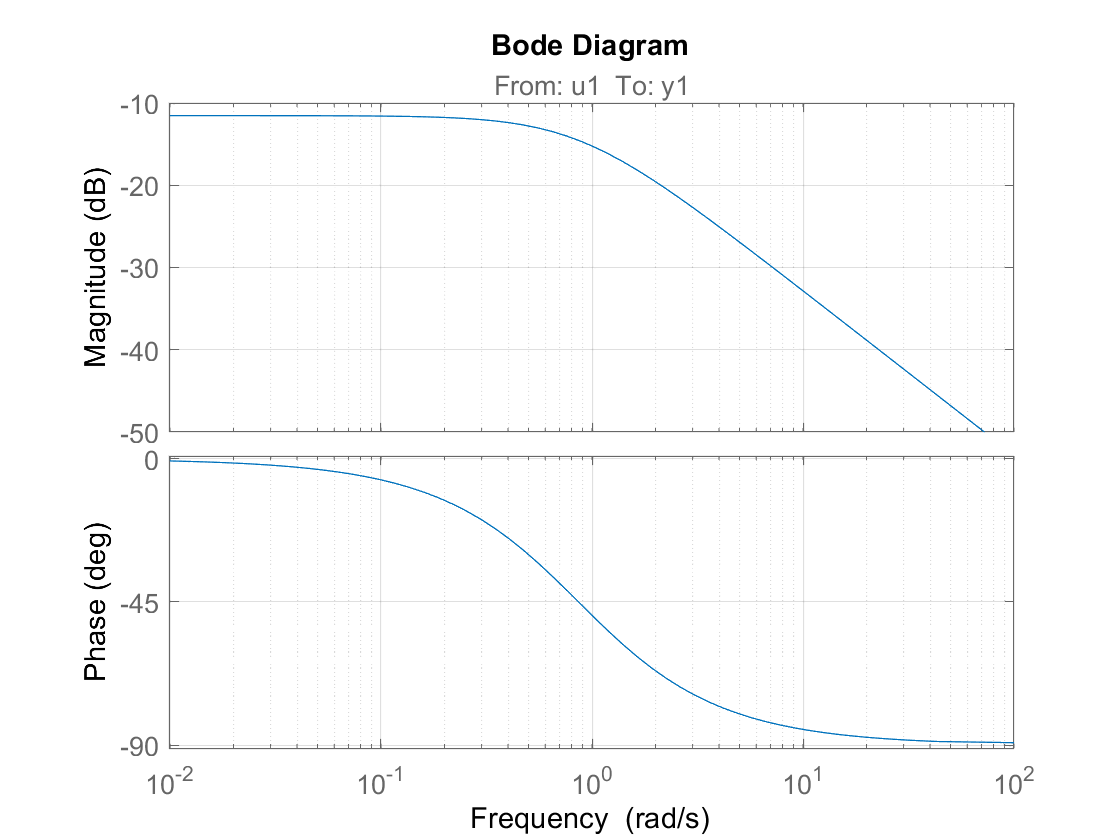


bode(sys)
grid on

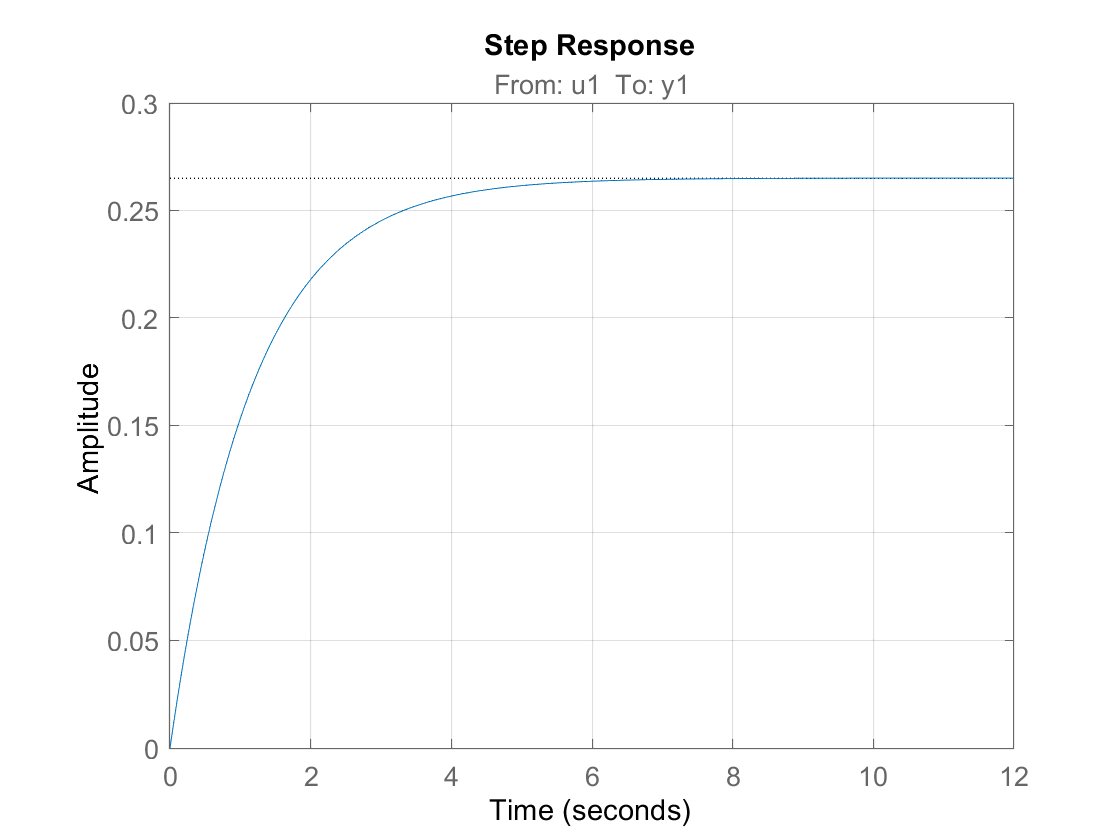

step(sys)
grid on

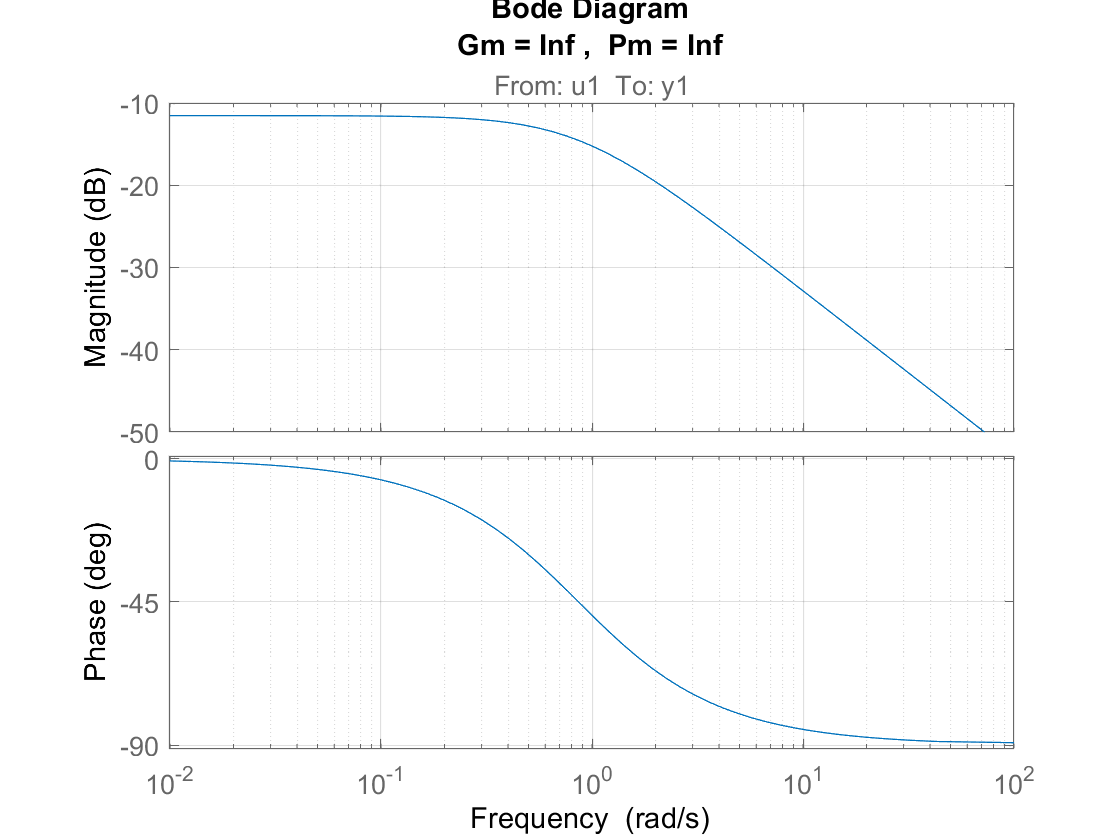


margin(sys)
grid on


G = sys;


## P- regulator

dbmag= -30
dbmag= -20

Kp = 10^(dbmag/20) %ca -17 aflæses fra bode plottet ved -180+fasemargin(60)
%så ved -120. samme frekvens findes i magnitude plottet, og dB aflæses 
%disp(Kp);

Gol_P = Kp*G
bode(Gol_P)
grid on
step(Gol_P)
grid on

poles_P = pole(Gol_P)
zeros_P = zero(Gol_P)

## med lukket sløjfe

%Kp_up = Kp * 25
Kp_up = Kp 
%Kp_up = 2
G_up = minreal(Kp_up*G/(1+G*Kp_up),1.0e-5)
step(G_up)

## PI regulator

## Ud fra phase


%vælger fasen ved -60 grader -> vi ligger nulpunktet i i-ledet 5-10 gange
%lavere end fasemargin frekvensen for en p-kontroller 
% sørg for at den endelige phasemargin er under 180- meget vigtigt, men det
% er på den endelige bode

bode(G)

% sim er 50Hz så båndbredden skal være omkring 10 gange lavere  

omega_c = 3;
tau_i = 1/omega_c


% Controller transfer
Ci = tf([tau_i 1],[tau_i 0]);     % I and PI zero
Gol_PI = Ci*G                    % open loop

bode(Gol_PI)


dbmag = 7.6 % rykker den en smule mere op i frekvens (er stadig under 180)
%dbmag = 22

Kp = 10^(dbmag/20) %ca -17 aflæses fra bode plottet ved -180+fasemargin(60)
%så ved -120. samme frekvens findes i magnitude plottet, og dB aflæses 
%disp(Kp);
Kp = 2
Gol_PI_r = Kp*Ci*G                    % open loop

bode(Gol_PI_r)

G_close = minreal(Gol_PI_r/(1+Gol_PI_r),0.1e-5)
step(G_close)



Ni       =  3;
gamma_m  = 60; % fasemargin


phi_PI   = -90 + atan(Ni)*180/pi;
arg      = -180 + gamma_m - phi_PI

% aflæs i phase plot på phase(arg) 
omega_c  = 0.2073

tau_i = Ni/omega_c


%hvor meget ønsker vi at løfte eller sænke? (+ for løfte, - for sænke)sæt
%ind her ved dbmag
dbmag=61.47
Kp = 10^(dbmag/20)



% Controller transfer
Ci = tf([tau_i 1],[tau_i 0]);     % I and PI zero
Gol_PI = Kp*Ci*G                     % open loop

bode(Gol_PI)
grid on 
poles_PI = pole(Gol_PI)
zeros_PI = zero(Gol_PI)
step(Gol_PI)
grid on

## Design af PID

## PID ud fra phasen

%vælger fasen ved -60 grader -> vi ligger nulpunktet i i-ledet 5-10 gange
%lavere end fasemargin frekvensen for en p-kontroller 
% sørg for at den endelige phasemargin er under 180- meget vigtigt, men det
% er på den endelige bode

alpha = 0.002;


bode(G)

% sim er 50Hz så båndbredden skal være omkring 10 gange lavere  

omega_c = 3;
tau_i = 1/omega_c;

tau_d = 1/(omega_c*sqrt(alpha));

% Controller transfer
Ci = tf([tau_i 1],[tau_i 0]);         % I and PI zero
Cd = tf([tau_d 1],[alpha*tau_d 1]);   % lead
Gol_PID_phase = Ci*Cd*G                      % open loop

bode(Gol_PID_phase)



dbmag = -19.444 % rykker den en smule mere op i frekvens (er stadig under 180)
dbmag = -1

Kp = 10^(dbmag/20) %ca -17 aflæses fra bode plottet ved -180+fasemargin(60)
%så ved -120. samme frekvens findes i magnitude plottet, og dB aflæses 
%disp(Kp);

Gol_PID_p = Kp*Cd*Ci*G                    % open loop

bode(Gol_PID_p)

G_close = minreal(Gol_PID_p/(1+Gol_PID_p),0.1e-5)
step(G_close)

## bog_metode


Ni       = 3 ;% (100/80);
alpha    = 0.2;
gamma_m  = 60; % fasemargin

phi_lead = asin((1-alpha)/(1+alpha))*180/pi;
phi_PI   = -90 + atan(Ni)*180/pi;
arg      = -180 + gamma_m -phi_lead - phi_PI

% aflæs i phase plot på phase(arg) 
omega_c  = 0.077337;
%omega_c  = 1;

tau_i    = Ni/omega_c
tau_d    = 1/(omega_c*sqrt(alpha))


%hvor meget ønsker vi at løfte eller sænke? (+ for løfte, - for sænke)
dbmag=-0.2178
%dbmag=+18
%dbmag=+0.00001;
Kp = 10^(dbmag/20)


% Controller transfer
Ci = tf([tau_i 1],[tau_i 0]);         % I and PI zero
Cd = tf([tau_d 1],[alpha*tau_d 1]);   % lead
Gol_PID = Kp*Ci*Cd*G                     % open loop


bode(Gol_PID)
grid on 
poles_PID = pole(Gol_PID)
zeros_PID = zero(Gol_PID)
step(Gol_PID)


## PD

alpha    = 2;
gamma_m  = 60; % fasemargin

phi_lead = asin((1-alpha)/(1+alpha))*180/pi;
arg      = -180 + gamma_m -phi_lead - phi_PI

% aflæs i phase plot på phase(arg) 
omega_c  = 0.077337;
%omega_c  = 1;

tau_d    = 1/(omega_c*sqrt(alpha))

%hvor meget ønsker vi at løfte eller sænke? (+ for løfte, - for sænke)
dbmag = 0.55
Kp = 10^(dbmag/20)


% Controller transfer
Cd = tf([tau_d 1],[alpha*tau_d 1]);   % lead
Gol_PD = Kp*Cd*G                      % open loop


bode(Gol_PD)
grid on 
poles_PD = pole(Gol_PD)
zeros_PD = zero(Gol_PD)
step(Gol_PD)











## %% Sim Plot

x_plot = x.Data;
y_plot = y.Data;
psi_plot = psi.Data;



u = 0.02*sin(psi_plot);
v = 0.02*cos(psi_plot);
figure
scatter(y_plot,x_plot,'.')
hold on
quiver(y_plot-u/2,x_plot-v/2,u,v,'AutoScale','off')
daspect([1 1 1])
xlabel('y position','FontSize',12)
ylabel('x position','FontSize',12)
legend({'Position (y,x)','Orientation (psi)'},'Location','best')
title('pos and orientation')
box on
grid on


% figure
% 
% for i=1:length(x_plot)
%    scatter(y_plot(i),x_plot(i))
%    hold on 
%    
% end
% hold off
figure
plot(x_plot,y_plot)


figure
plot(x.time,x_plot)
legend({'x [m]','time [s]'},'Location','best')
title('x vs time')

figure
plot(y.time,y_plot)
legend({'y [m]','time [s]'},'Location','best')
title('y vs time')




alpha_flag_ = alpha_flag_1.Data 
time_flag_ = alpha_flag_1.Time

alpha_old_ = alpha_old_1.Data
time_old_ = alpha_old_1.Time

alpha_new_ = alpha_new_1.Data
time_new_ = alpha_new_1.Time

figure
scatter(time_flag_,alpha_flag_)

figure
plot(time_old_,alpha_old_)
hold on
plot(time_new_,alpha_new_)
hold off



figure
scatter(time_flag_,alpha_flag_)
hold on
plot(time_old_,alpha_old_)
plot(time_new_,alpha_new_)
hold off




## Discritisation


syms tau_i

tau_i = 1
Kw = 0.9
Delta = 2

int_1 = tf([tau_i+1],[tau_i 0])

int_2 = tf([Kw*Delta],[1 0])


int = int_1+int_2





## model

model = "simulink_30_03"

load_system(model);
open_system(model);

## u surge controllers

ios(1) = linio("simulink_30_03/u_input",1,'openinput')
ios(2) = linio("simulink_30_03/u_output",1,'openoutput')

setlinio(model,ios);


op = [29]
%op = [0.1]

sys = linearize(model,ios,op); 
%sys = linearize(model,ios,op)



% opspec = operspec(model);
% op = findop(model,opspec,findopOptions('DisplayReport','off'));
% linsys = linearize(model,op, ios);
% 
% 
% input = frest.createStep(...
%     'Ts',0.02,...
%     'StepTime',1,...
%     'StepSize',1e-5,...
%     'FinalTime',100);
% % Simulate the Simulink model using the input signal. simout is the simulated output of the nonlinear model.
% 
% [~,simout] = frestimate(model,op,ios,input);
% % Simulate the linear model sys, and compare the time-domain responses of the linear and nonlinear Simulink model. The step response of the nonlinear model and linearized model are close, which validates that the linearization is accurate.
% 
% frest.simCompare(simout,linsys,input)
% legend('FRESTIMATE results with Custom input',...
% 			'Linear simulation of linsys with Custom input',...
% 			'Location','SouthEast')


M = 1;

[num, den] = ss2tf(sys.A(:,:,M), sys.B(:,:,M), sys.C(:,:,M), sys.D(:,:,M))
ghv = minreal(tf(num,den), 0.005)

bode(ghv)



% %%

% figure(1)

% hold off

% for M = 1:size(op,2)

%     [num, den] = ss2tf(sys.A(:,:,M), sys.B(:,:,M), sys.C(:,:,M), sys.D(:,:,M));

%     ghv = minreal(tf(num,den), 0.05)

%     bode(ghv)

%     hold on

% end

% grid on

% title("surge (u) velocity")

## v sway

ios(1) = linio("simulink_30_03/v_input",1,'openinput')
ios(2) = linio("simulink_30_03/v_output",1,'openoutput')

setlinio(model,ios);


op = [10, 5 , 1]
%op = [0.1]

sys = linearize(model,ios,op); 
%sys = linearize(model,ios,op)



figure(2)
hold off
for M = 1:size(op,2)
    [num, den] = ss2tf(sys.A(:,:,M), sys.B(:,:,M), sys.C(:,:,M), sys.D(:,:,M));
    ghv_v = minreal(tf(num,den), 0.05)
    bode(ghv_v)
    hold on
end
grid on
title("Sway (v) velocity")




## Yaw (tau)

ios(1) = linio("simulink_30_03/tau_input1",1,'openinput')
ios(2) = linio("simulink_30_03/yaw_output",1,'openoutput')

setlinio(model,ios);


op = [10, 5 , 1]
%op = [0.1]

sys = linearize(model,ios,op); 
%sys = linearize(model,ios,op)



figure(1)
hold off
for M = 1:size(op,2)
    [num, den] = ss2tf(sys.A(:,:,M), sys.B(:,:,M), sys.C(:,:,M), sys.D(:,:,M));
    ghv_tau = minreal(tf(num,den), 0.05)
    bode(ghv_tau)
    hold on
end
grid on
title("Yaw (tau)")

% figure(1)








sys_u = load('sys_u.mat')
sys_u = sys_u.linsys4

pole(sys_u)

bode(sys_u)
step(sys_u)

## u (P )

G1 = tf(sys_u)

% phasemargin
gm = 3;
% omega frequency 
w = logspace((-15),15,10000)


[wc, Kp, ok] = findp(G1, gm, w)


## u (PI)

## u (PD)

## u (PID)


Ni = 2;
al = 0.1;

[wc, Kp, taui, taud, ok] = findpid(G1, gm, Ni, al, w)








## v sway controllers

% P - controller 
[wc, Kp, ok] = findp(G1, gm, w)








## psi yaw P controller

% P - controller 
[wc, Kp, ok] = findp(G1, gm, w)